# ECE 808 Smart Water Networks (Lecture 3)

**Load paths**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## **Analyzing SCADA data**

- A key aspect in Smart Water Systems, is being able to process real data

- Let's plot some real data

- Notice the spikes in the data! Are these real measurements?

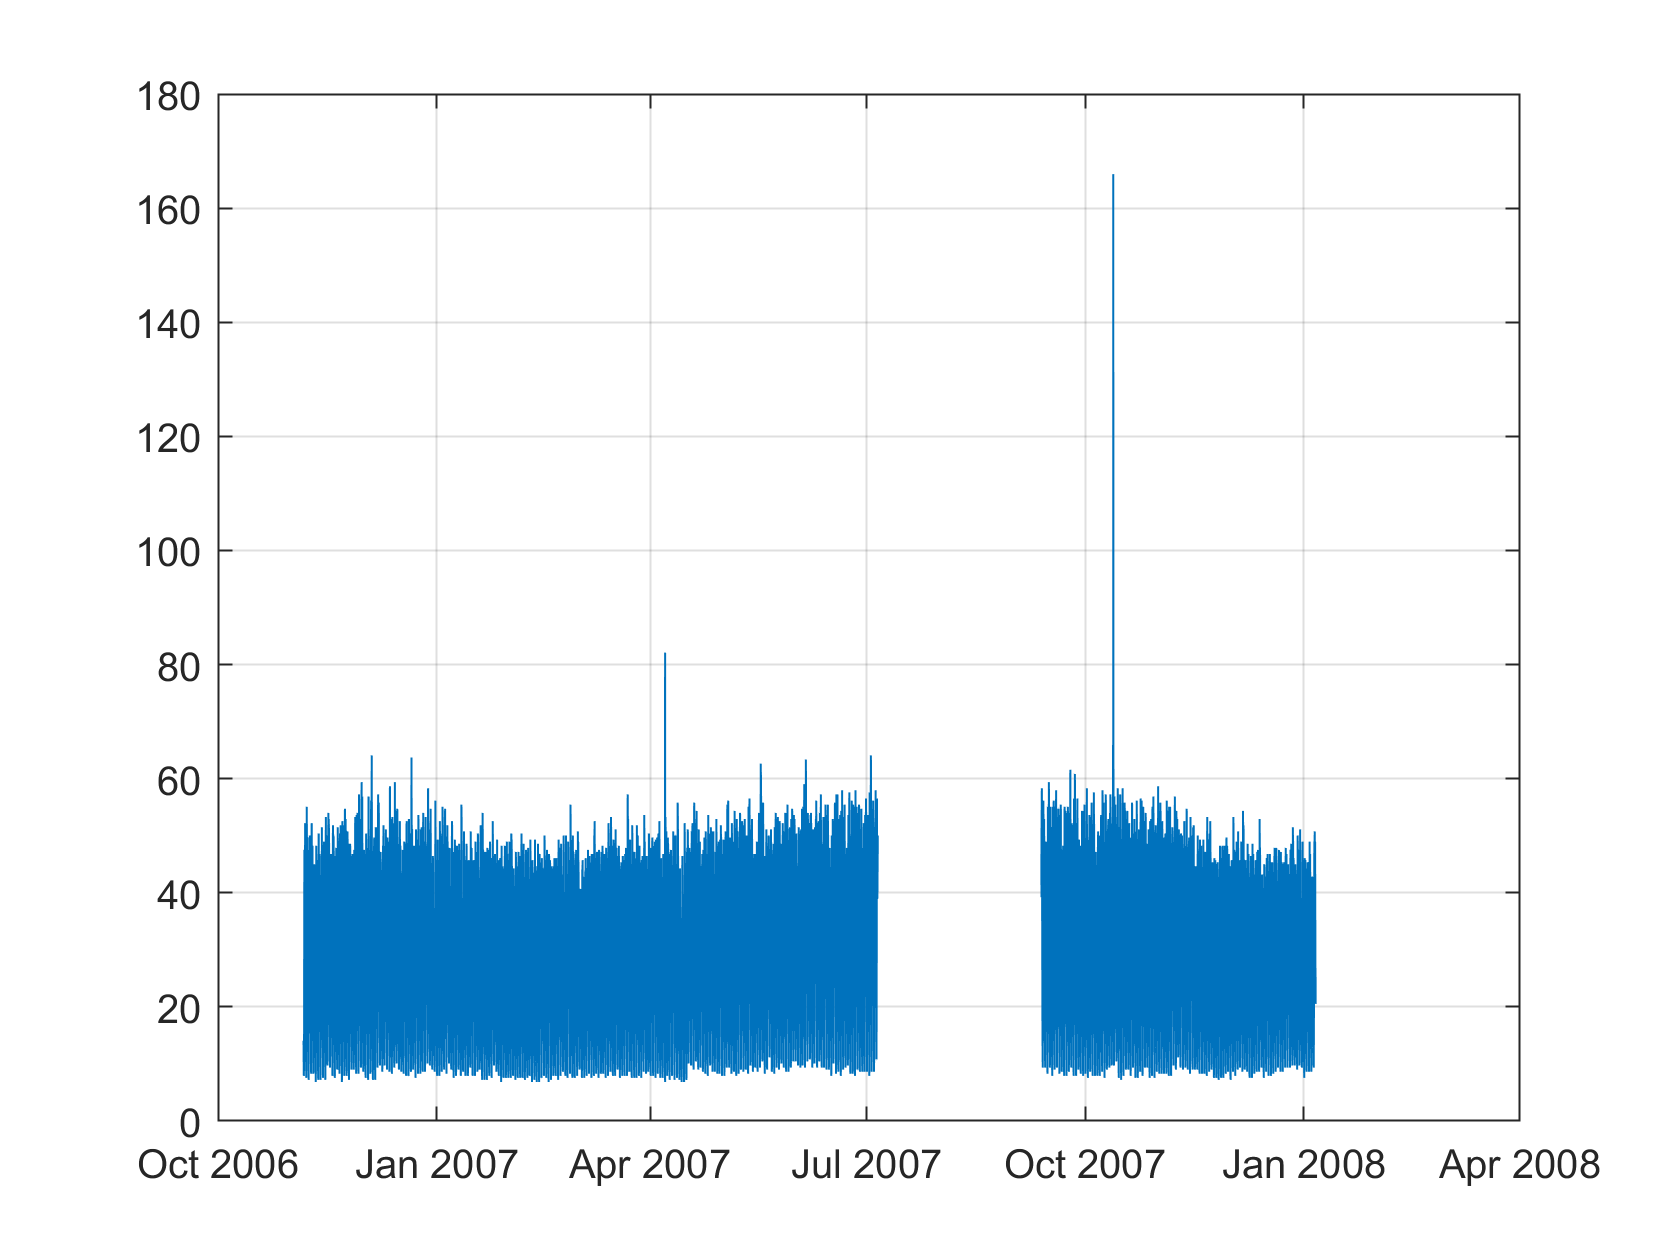

load SCADA.mat % import SCADA

figure
plot(Tsim, Flow)
grid on

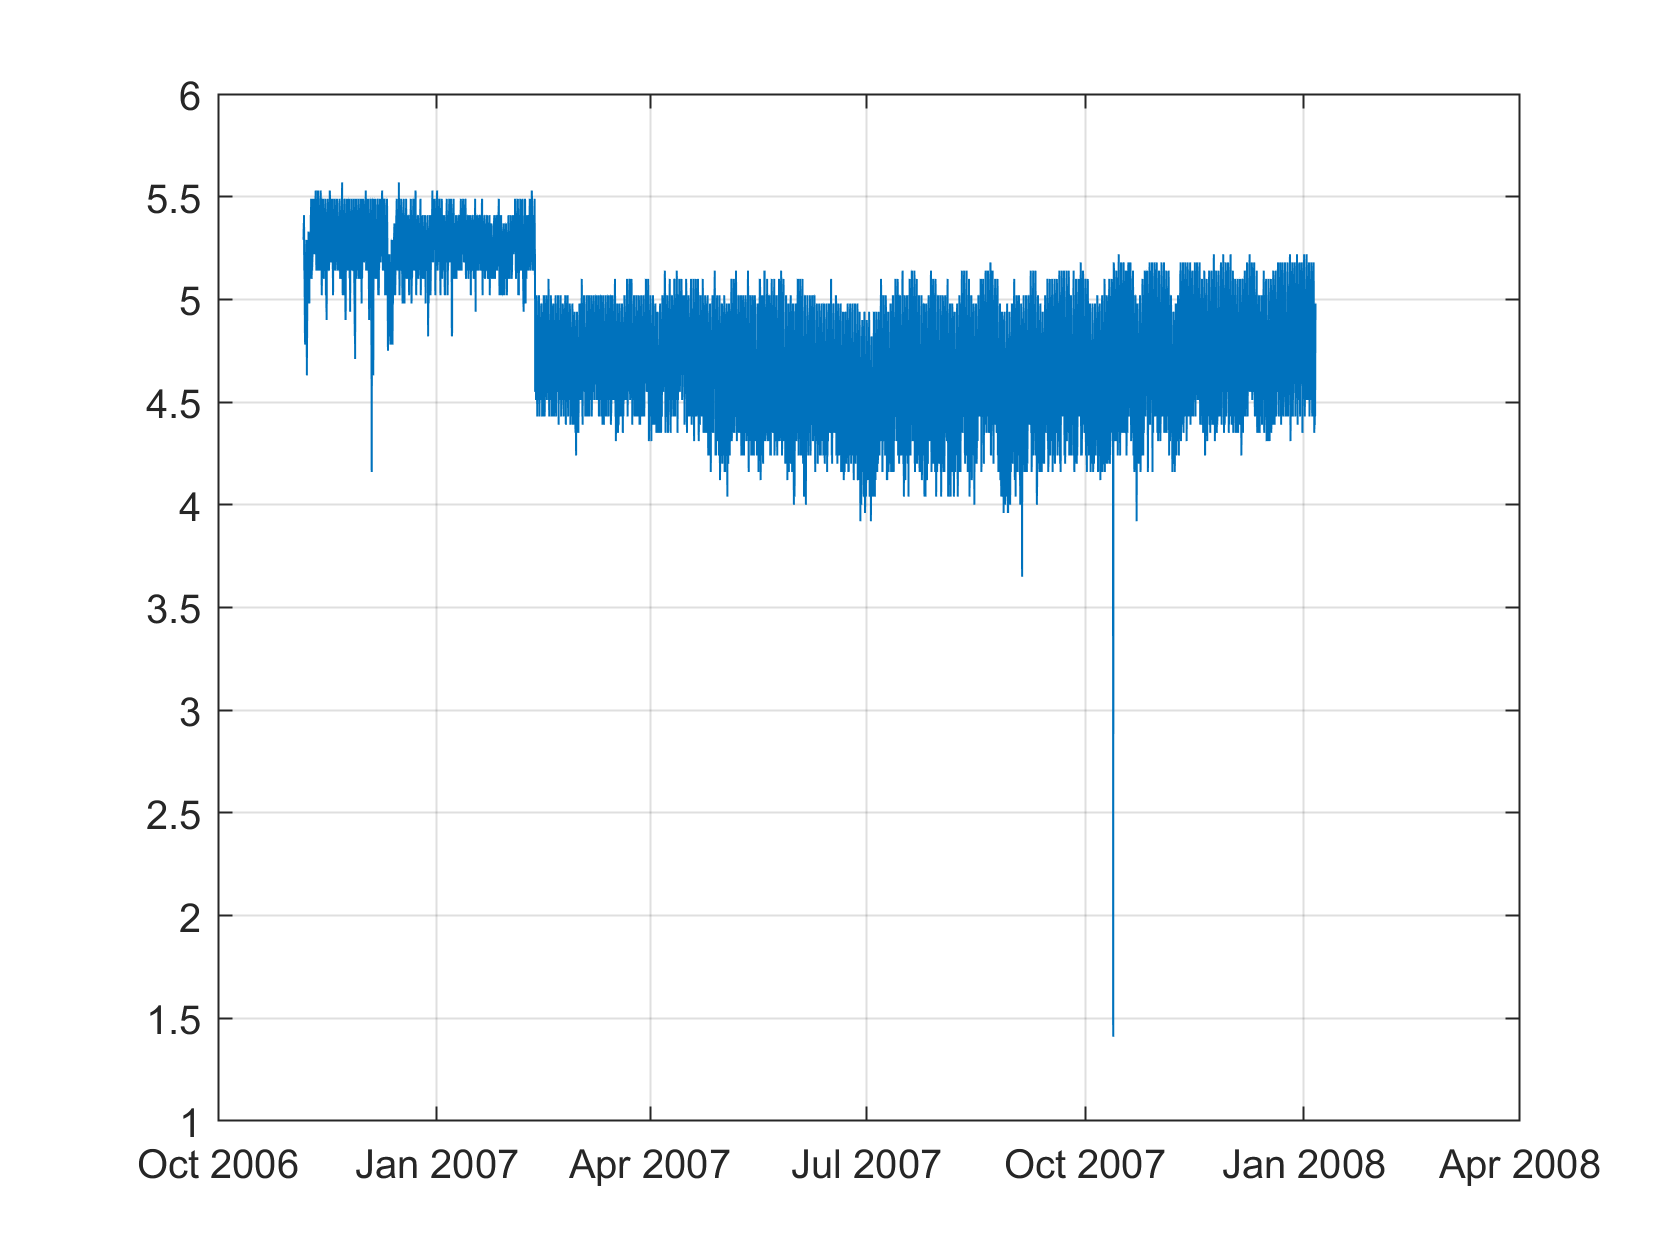


figure
plot(Tsim, Pressure)
grid on

**Let's go a bit deeper**

%how many days to plot
d = 7

d = 7

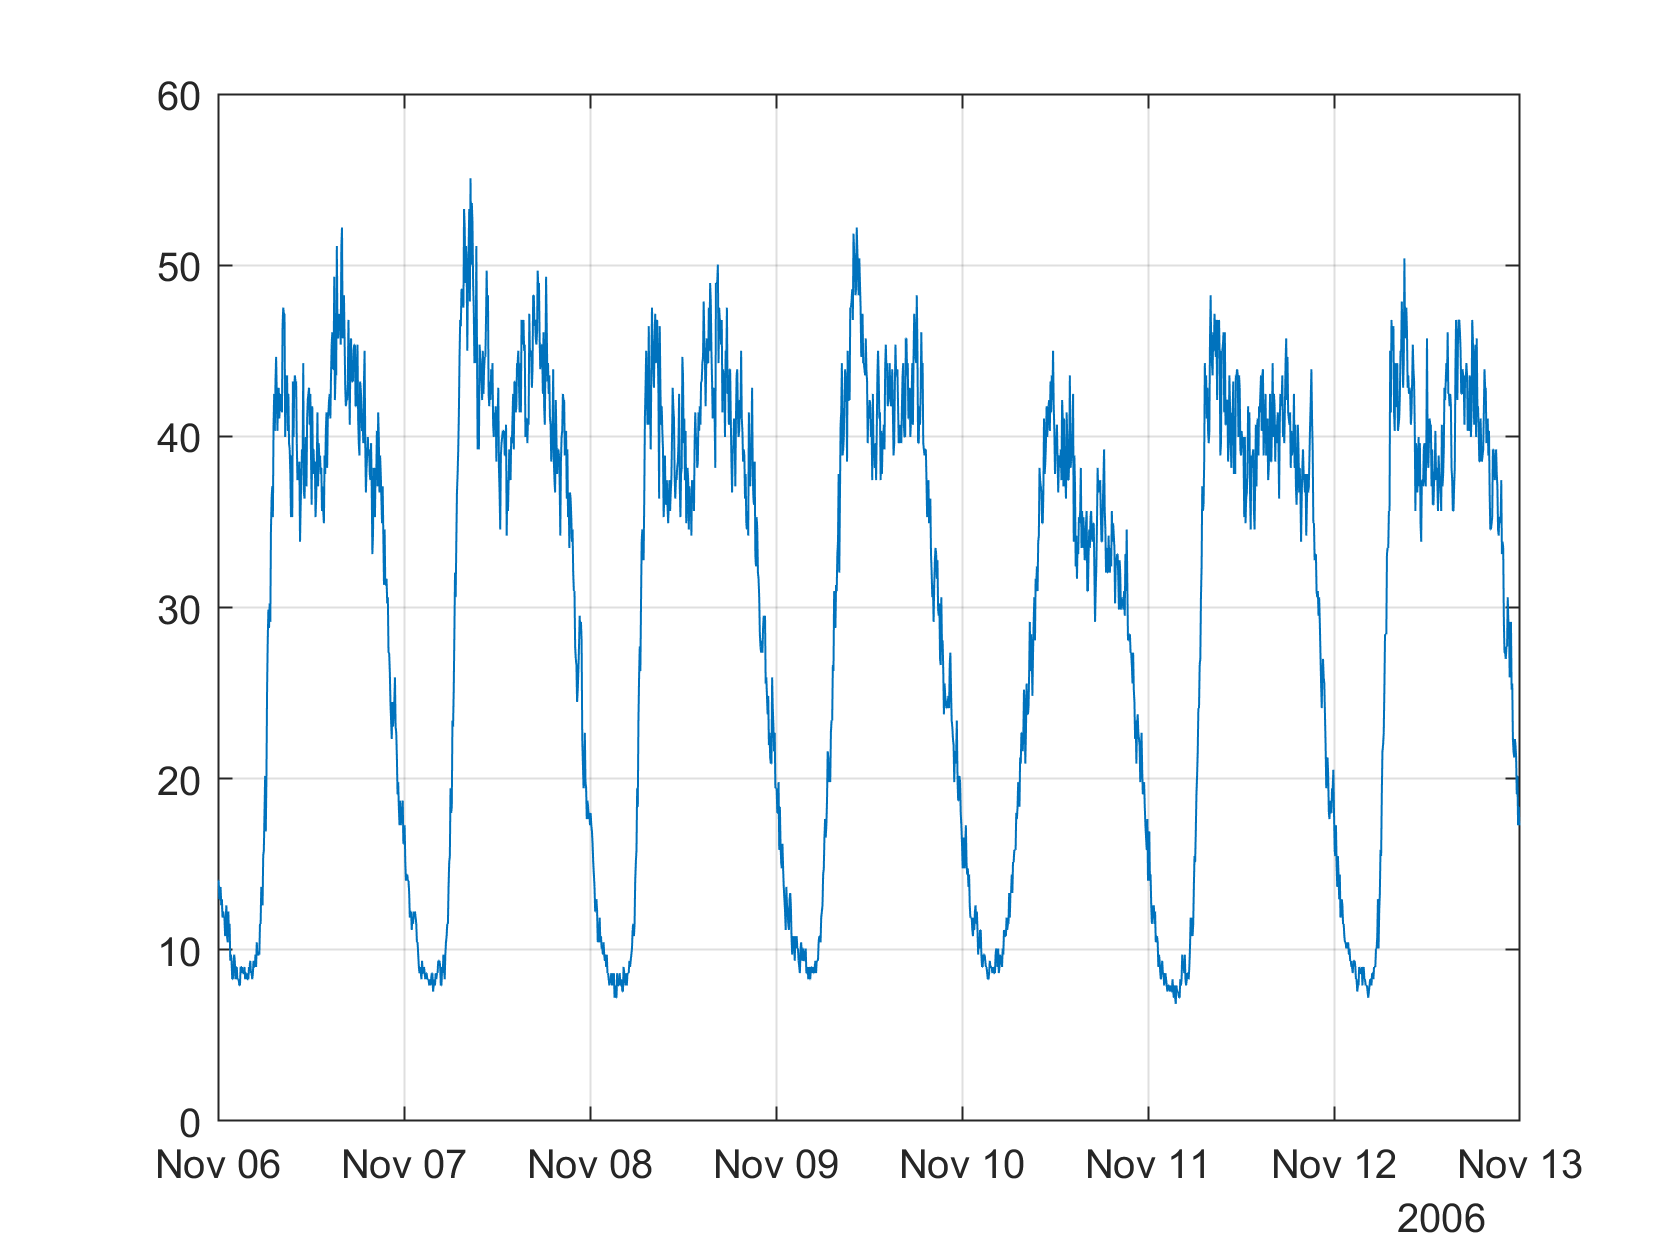

% compute time steps
D = 288*d;

figure
plot(Tsim(1:D), Flow(1:D))
grid on

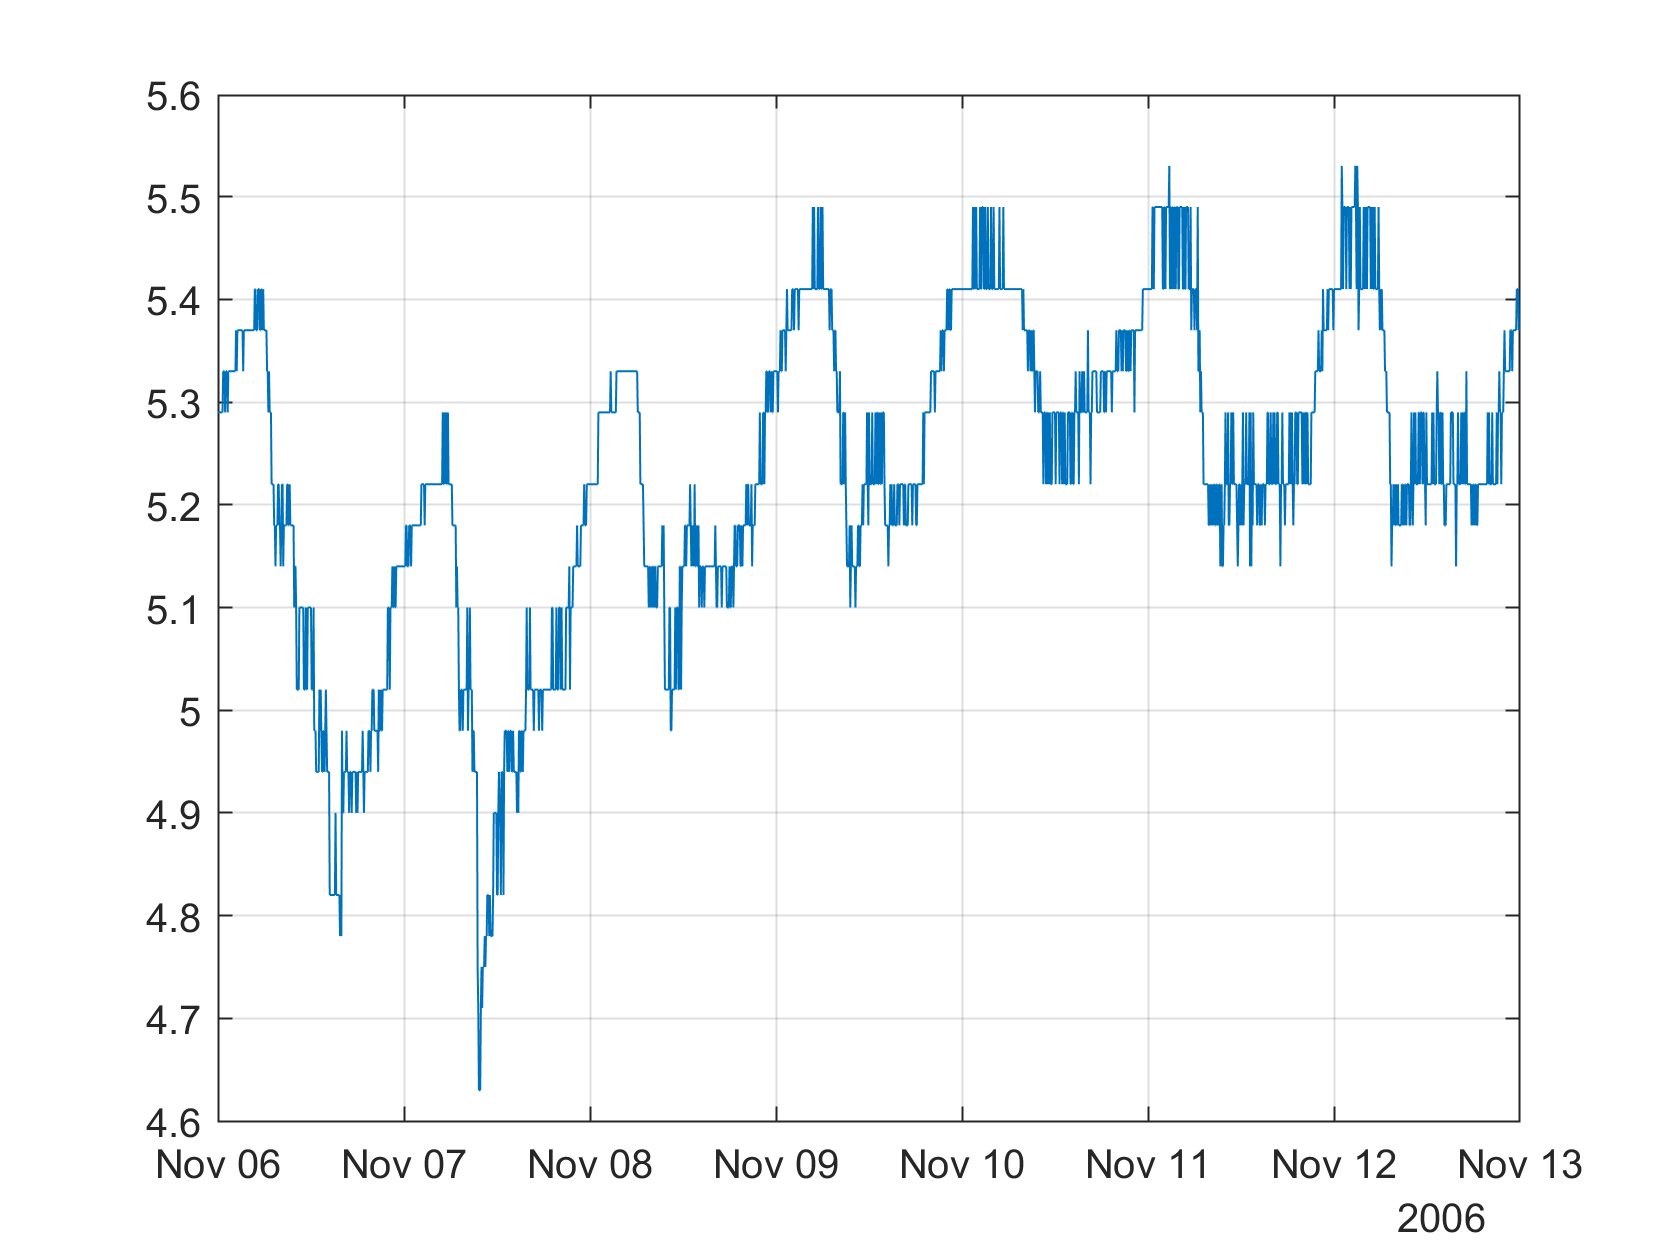


figure
plot(Tsim(1:D), Pressure(1:D))
grid on

**What do we observe?**

- Periodicity (weekly)

- Outliers

- Changes in the mean (pressure drop, leakage)

- Missing data

A possible outlier

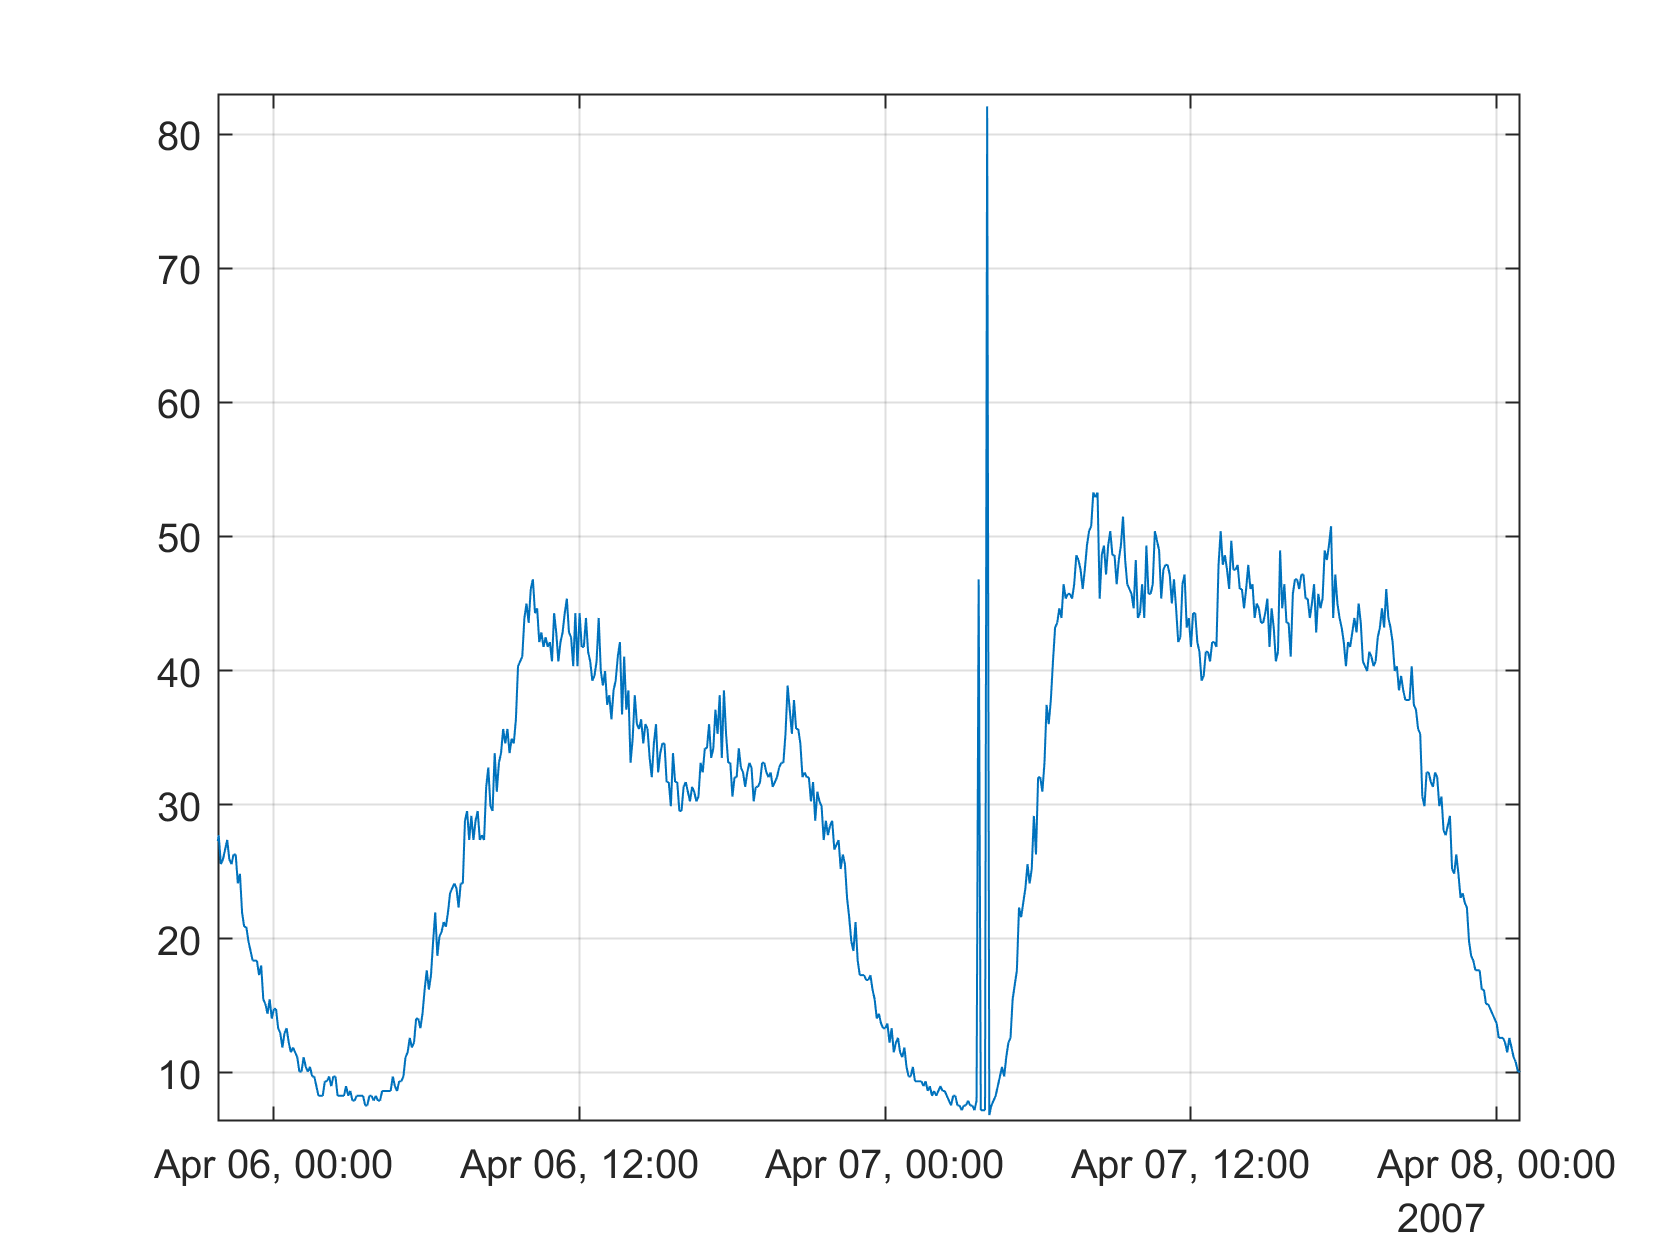

figure
plot(Tsim, Flow)
grid on

xlim([datetime(2007,4,5,21,48,19)...
      datetime(2007,4,8,0,55,2)])
ylim([6.4 83.0])

A possible leakage

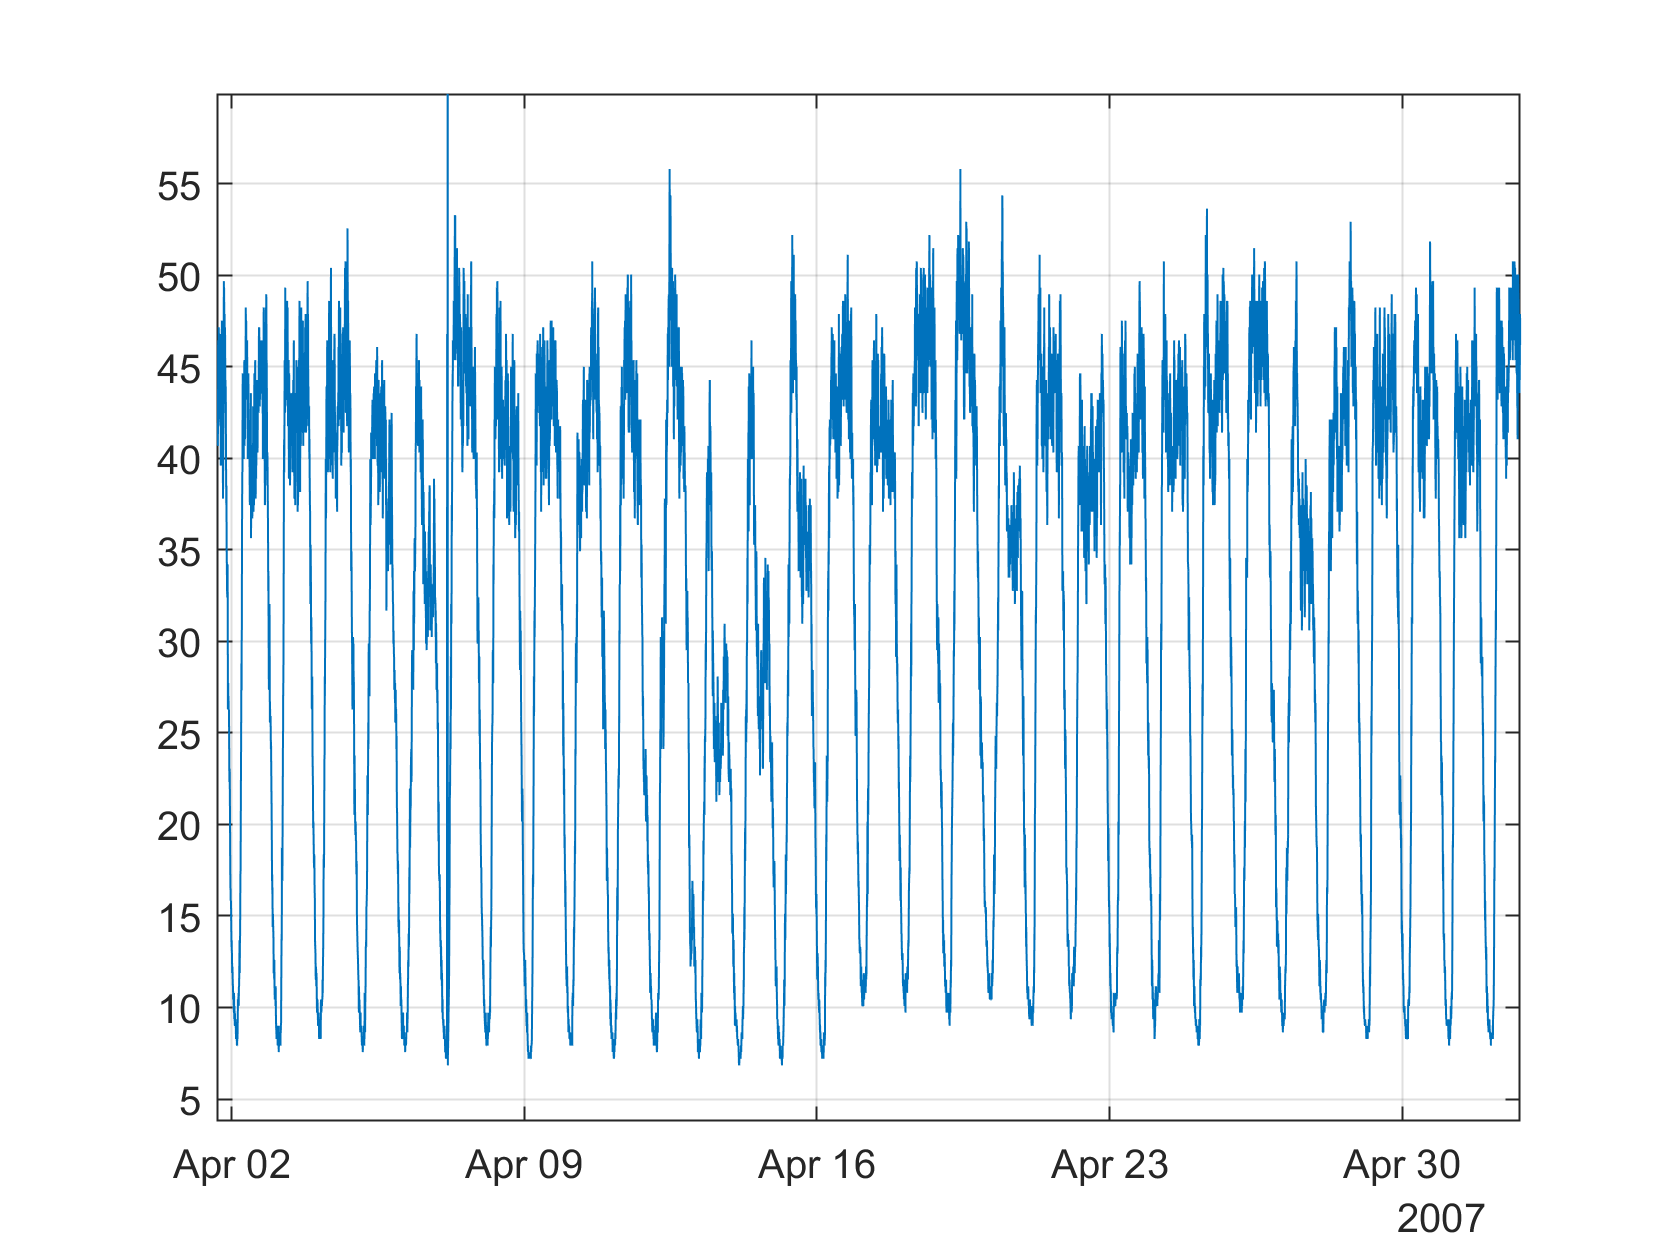

figure
plot(Tsim, Flow)
grid on
xlim([datetime(2007,4,1,16,8,11)...
      datetime(2007,5,2,19,38,19)])
ylim([3.8 59.9])

**Is this the real life?**

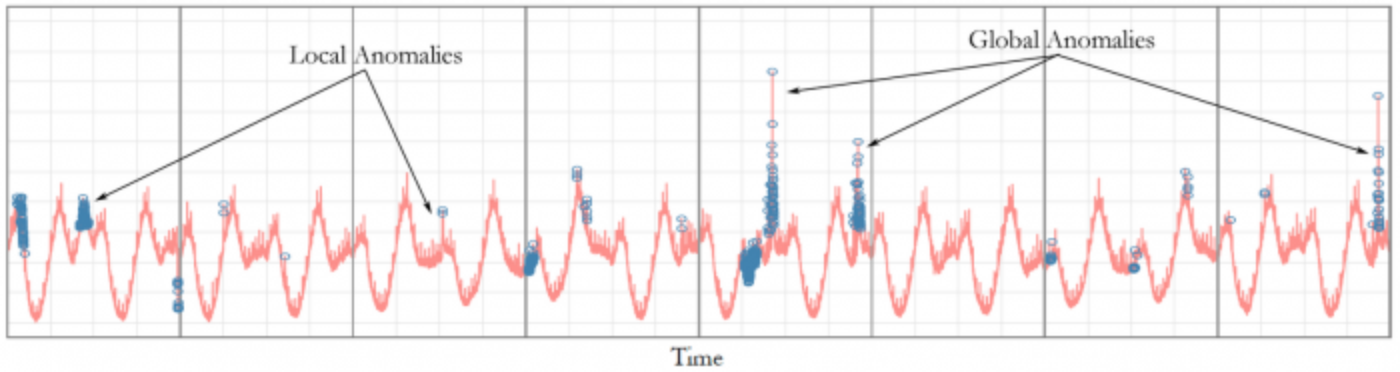

[Twitter Time Series Data](https://blog.twitter.com/engineering/en_us/a/2015/introducing-practical-and-robust-anomaly-detection-in-a-time-series.html)

### **As simple way to filter outliers**

- Median Absolute Deviation (MAD) algorithm

- Outlier is a value that is more than 3 scaled median absolute deviations

Choose a window length w 


$$X(k) = [x(k-w+1),..., x(k)]$$
 


$$X_m(k) = median(X(k))$$



$$MAD(k) = median(|X(k)-X_m(k)|)$$


Assuming a normal distribution of $X(k)$, this is multiplied with a scale factor $sMAD = 1.4826\times MAD$.

outliers are typically beyond $3 \times sMAD$.

**How to handle outliers?**

- Ignore them

- Replace them with some other value

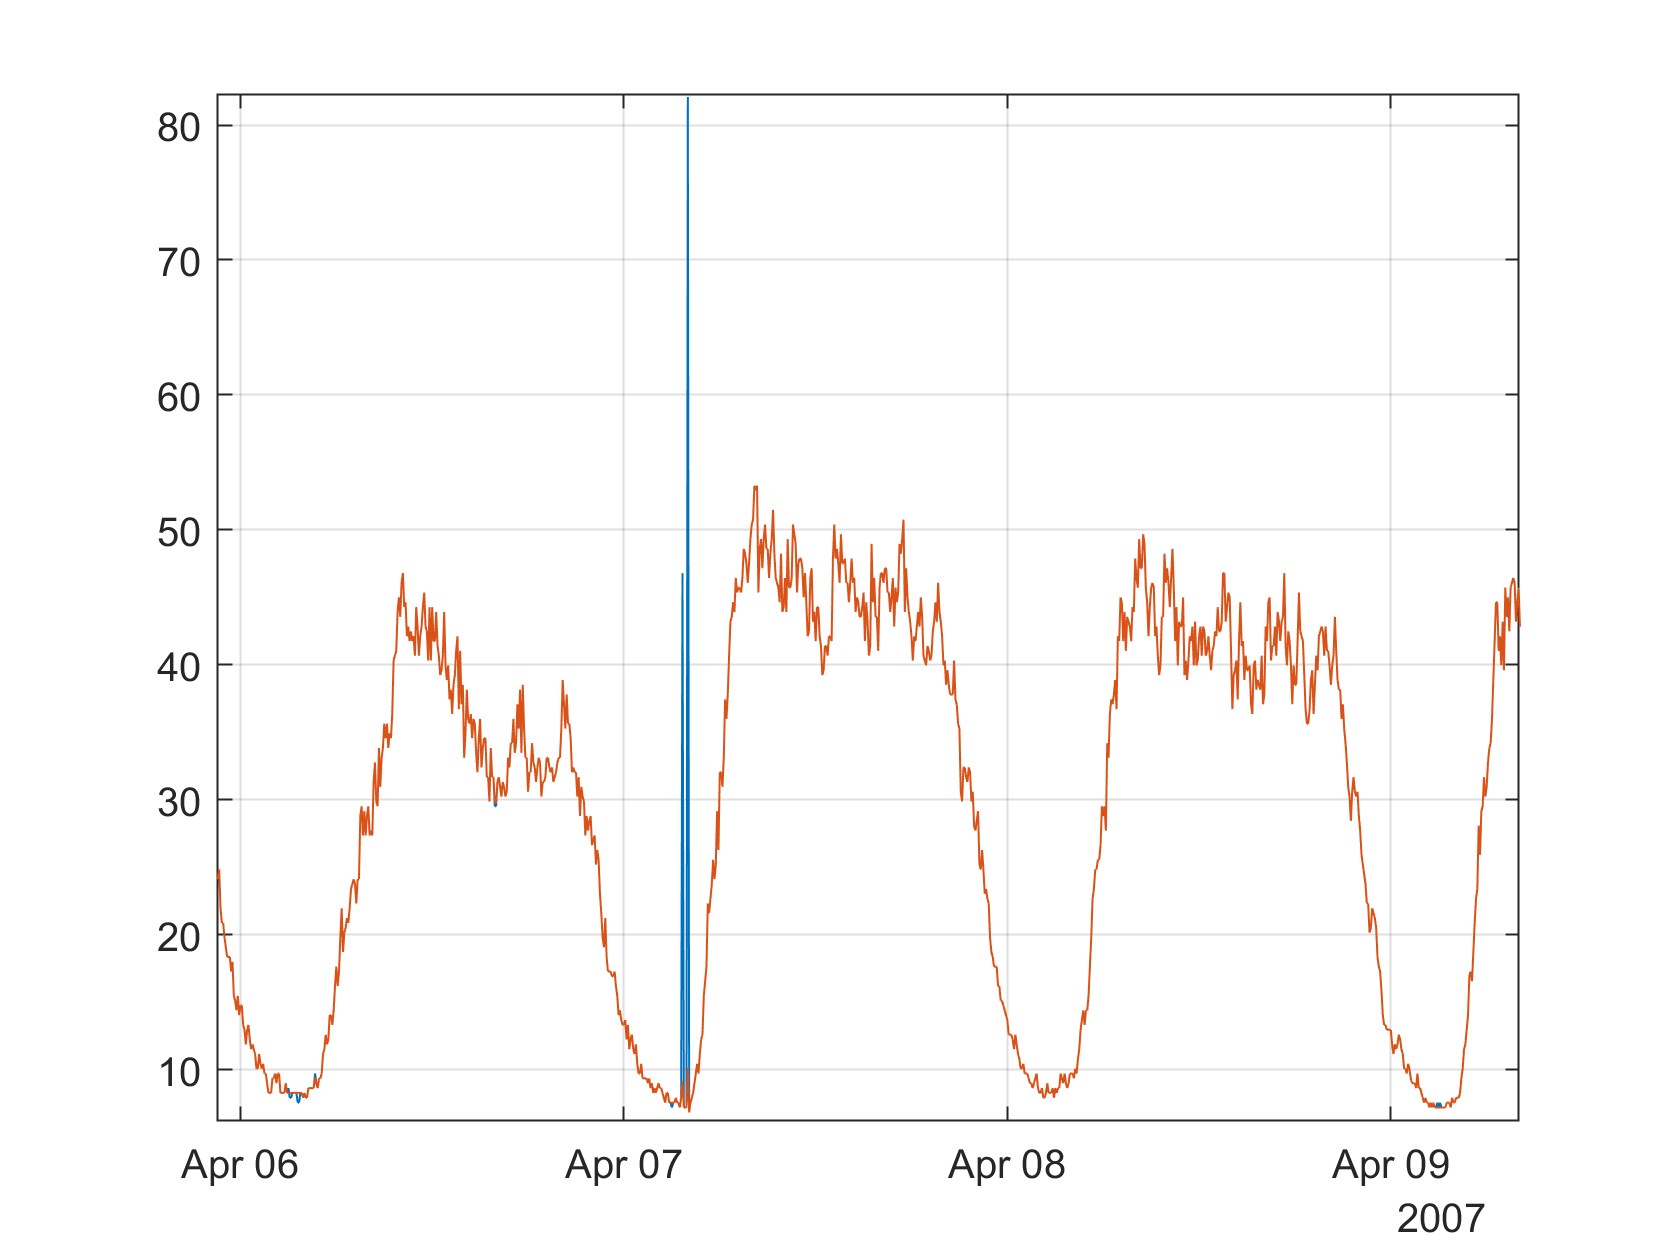

[B,TF,U,L,C] = filloutliers(Flow,'clip','movmedian',hours(1),'SamplePoints',Tsim);

figure
plot(Tsim,Flow);
hold all
plot(Tsim, B);
grid on
xlim([datetime(2007,4,5,22,35,34)...
      datetime(2007,4,9,8,5,11)])
ylim([6.2 82.3])

### **Data periodicity**

- **Water demands exhibit daily/weekly periodicy**

- **We can learn this using various approximation functions**

%how many days to plot
d = 7

d = 7

% compute time steps
D = 288*d;

KD = (1:D)';
TD = Tsim(KD);
FD = Flow(KD);

figure
plot(TD, FD)
grid on

**Fourier Series**

- We can approximate any continuous periodic signal using a combination of sines and cosines


$$y = a_0 + \sum_{i=1}^{n} a_i \cos(iwx) + b_i \sin(iwx)$$


How do we find the weights $a_0, a_i, b_i$? We can solve a "curve fitting" problem using least squares.

f = fit(KD,FD,'fourier8')

f =      General model Fourier8:
     f(x) = 
               a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + 
               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w) + 
               a6*cos(6*x*w) + b6*sin(6*x*w) + a7*cos(7*x*w) + b7*sin(7*x*w) + 
               a8*cos(8*x*w) + b8*sin(8*x*w)
     Coefficients (with 95% confidence bounds):
       a0 =       30.24  (30.07, 30.41)
       a1 =      -13.27  (-13.57, -12.98)
       b1 =      -9.854  (-10.17, -9.534)
       a2 =       -1.24  (-1.562, -0.9172)
       b2 =      -6.956  (-7.205, -6.706)
       a3 =       2.526  (2.277, 2.775)
       b3 =       1.014  (0.7501, 1.278)
       a4 =      -1.469  (-1.722, -1.217)
       b4 =       1.102  (0.8394, 1.365)
       a5 =      -1.185  (-1.432, -0.9382)
       b5 =     -0.5819  (-0.8437, -0.3201)
       a6 =      0.6263  (0.3766, 0.8759)
       b6 =     -0.6494  (-0.8979, -0.4009)
       a7 =      0.4464  (

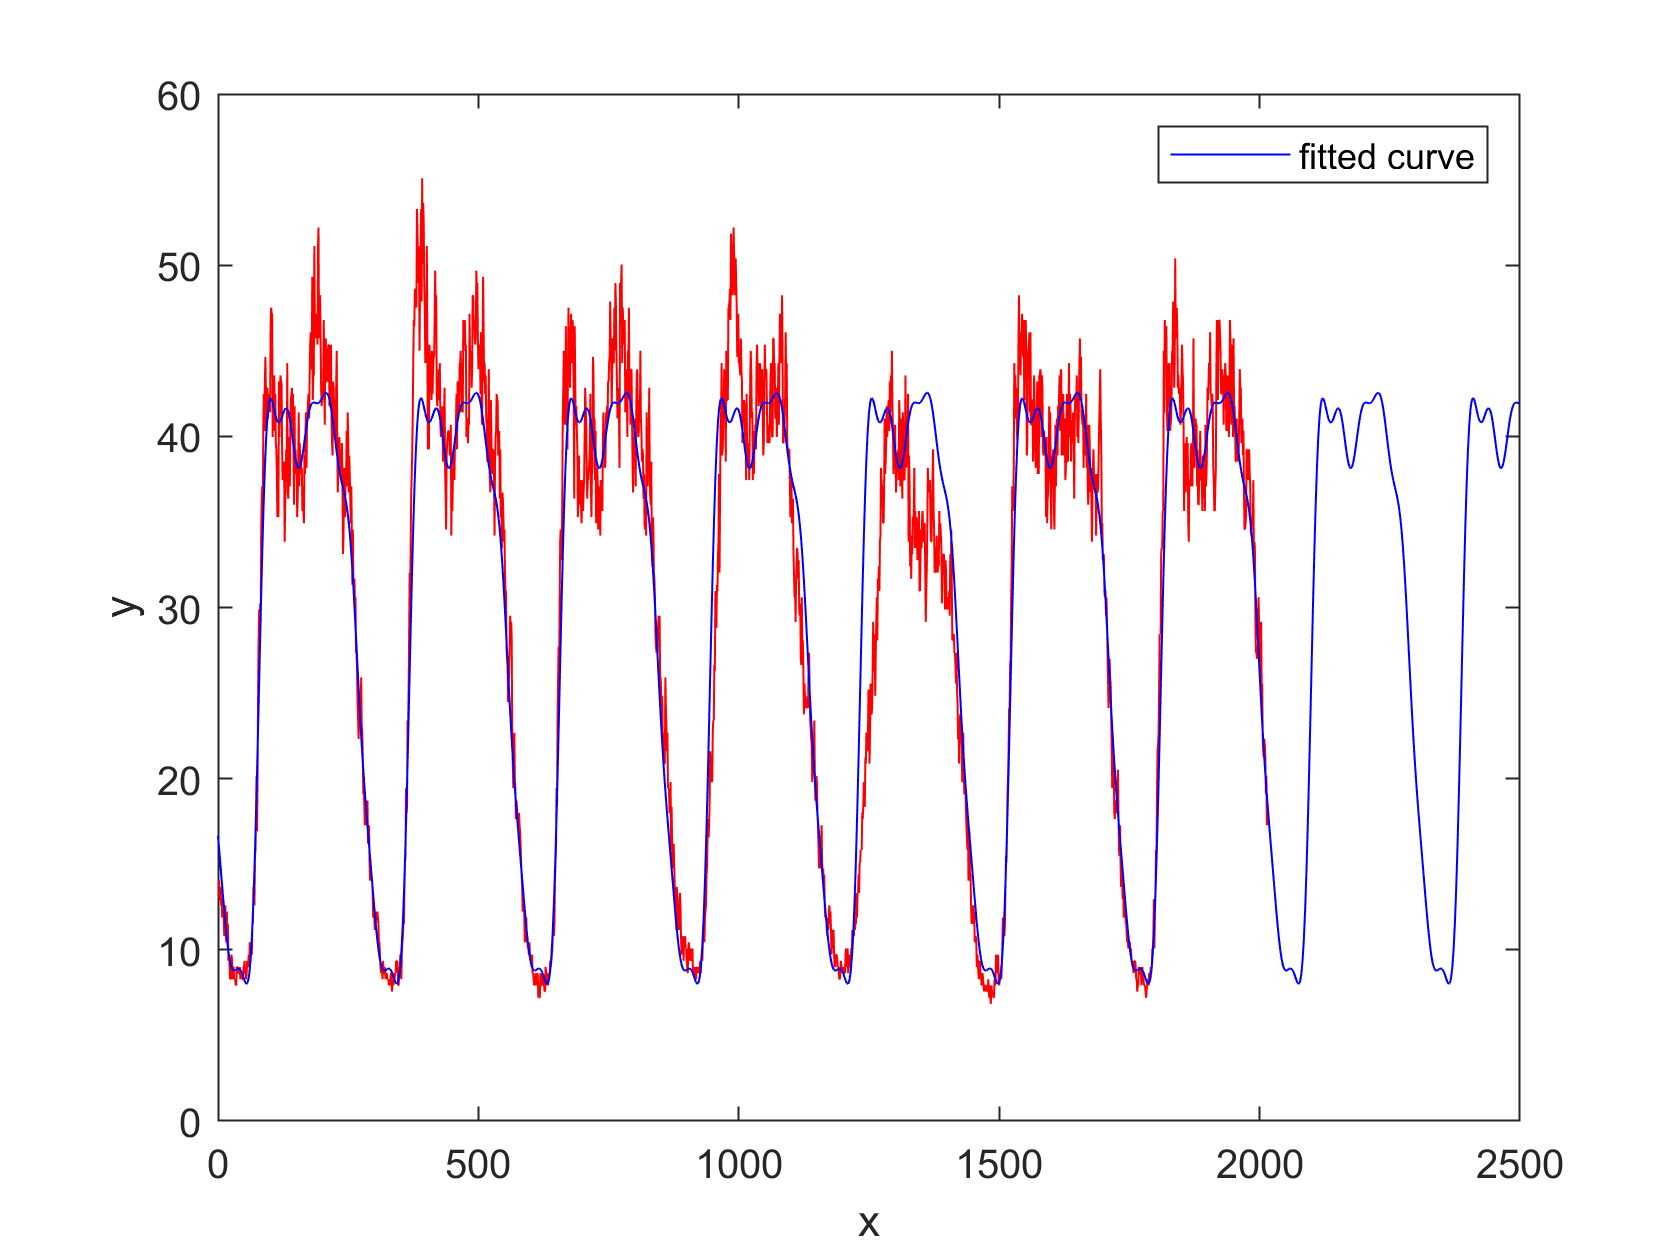

figure
plot(FD,'r')
hold all
plot(f,'b')

**Estimated periodicity**

per = 2 * pi / f.w % almost 288 = 5-minutes steps in 24 hours

per = 288.5858

**Improved model (daily pattern)**

coeffnames(f)

ans = 18×1 cell array
    {'a0'}
    {'a1'}
    {'b1'}
    {'a2'}
    {'b2'}
    {'a3'}
    {'b3'}
    {'a4'}
    {'b4'}
    {'a5'}
    {'b5'}
    {'a6'}
    {'b6'}
    {'a7'}
    {'b7'}
    {'a8'}
    {'b8'}
    {'w' }


coeffs = coeffvalues(f) 

coeffs =    30.2402  -13.2735   -9.8541   -1.2397   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4464    0.9460   -0.0035   -0.0562    0.0218


coeffs(18) = 2 * pi /288

coeffs =    30.2402  -13.2735   -9.8541   -1.2397   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4464    0.9460   -0.0035   -0.0562    0.0218


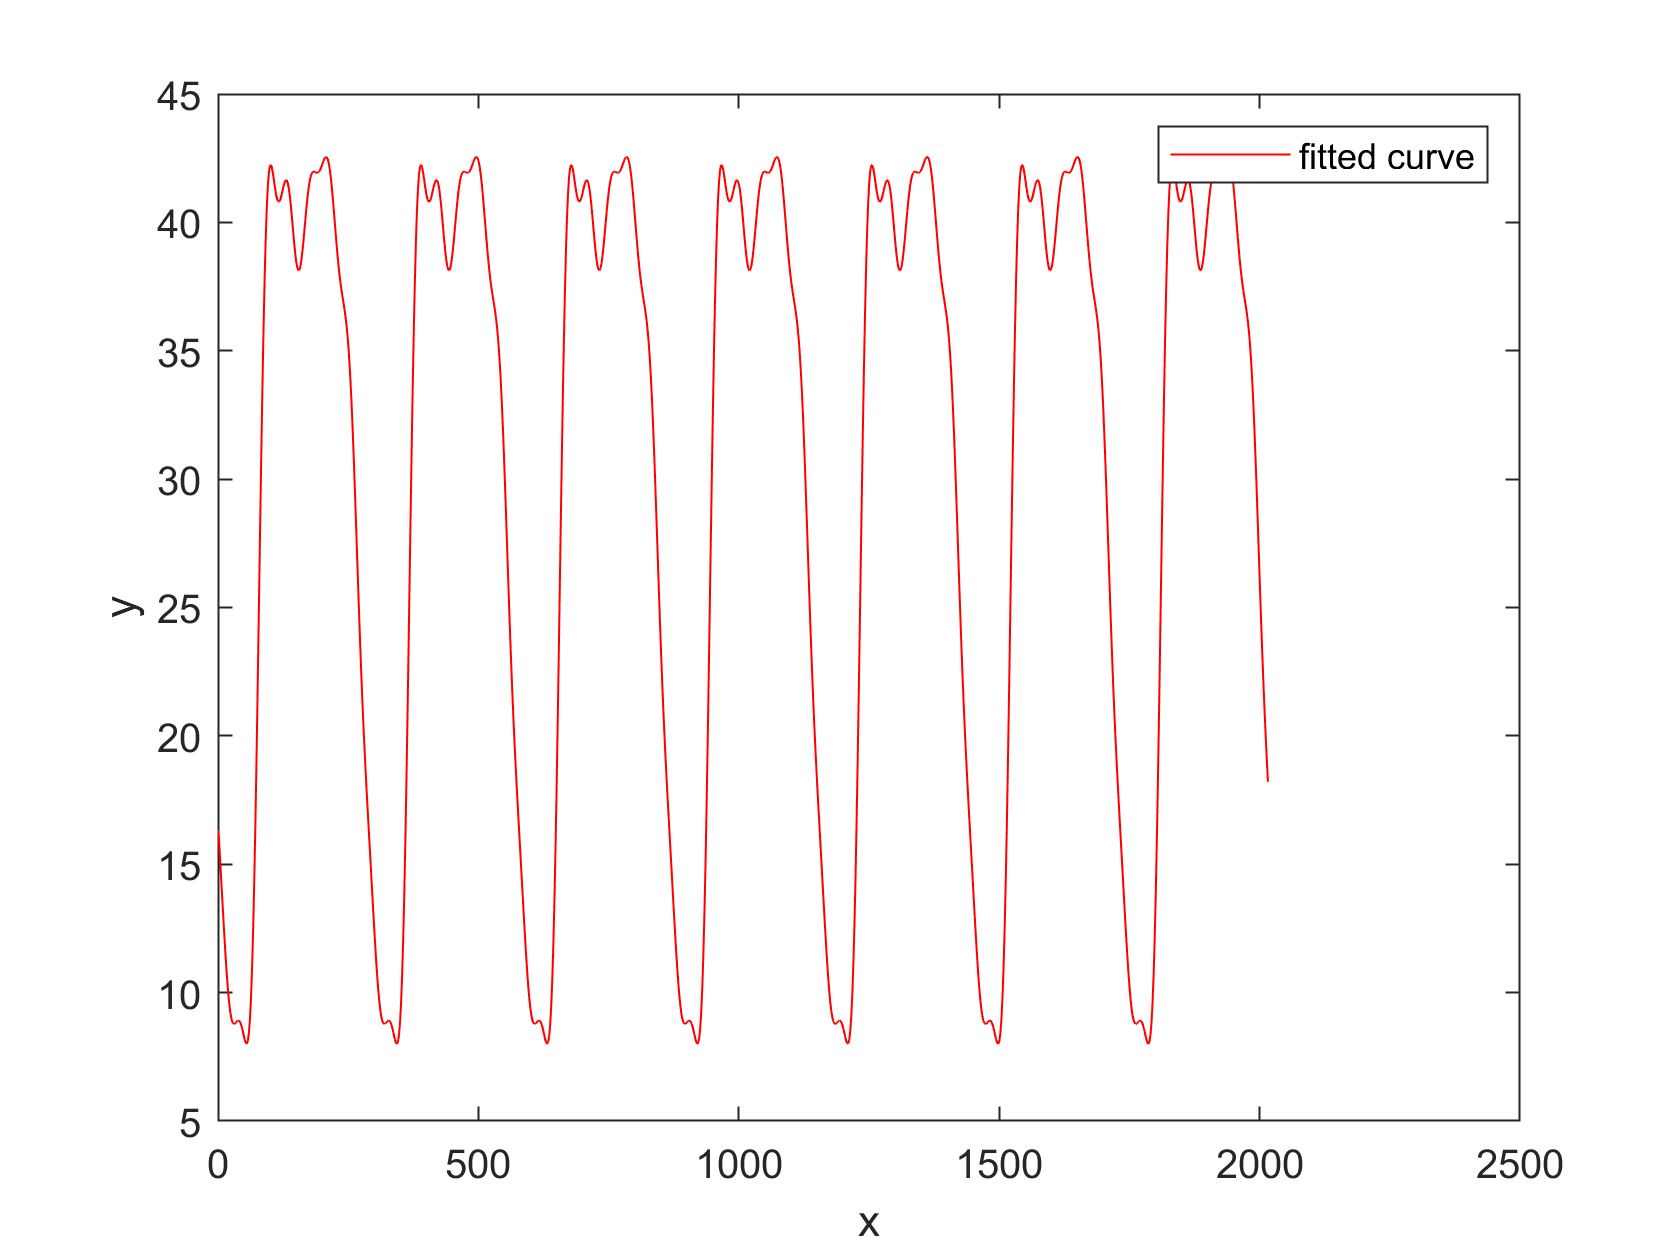

f2 = fit(KD,FD,'fourier8', 'StartPoint', coeffs);

figure
plot(f2)

### **Weekly periodicity**

%how many days to plot
dw = 30

dw = 30

% compute time steps
DW = 288*dw;

KDW = (1:DW)';
TDW = Tsim(KDW);
FDW = Flow(KDW);

ftmp = fit(KDW,FDW,'fourier8', 'StartPoint', coeffs);
perW = 2 * pi / ftmp.w /288 %in days, almost 7

perW = 1.0000


coeffs = coeffvalues(ftmp) 

coeffs =    31.0346  -13.2664  -10.6137   -0.4373   -7.0590    2.4445    1.4211   -1.6567    0.9168   -0.9146   -0.9074    0.6915   -0.4711    0.1149    1.0644    0.0721    0.0734    0.0218


coeffs(18) = 2 * pi /(288*7)

coeffs =    31.0346  -13.2664  -10.6137   -0.4373   -7.0590    2.4445    1.4211   -1.6567    0.9168   -0.9146   -0.9074    0.6915   -0.4711    0.1149    1.0644    0.0721    0.0734    0.0031


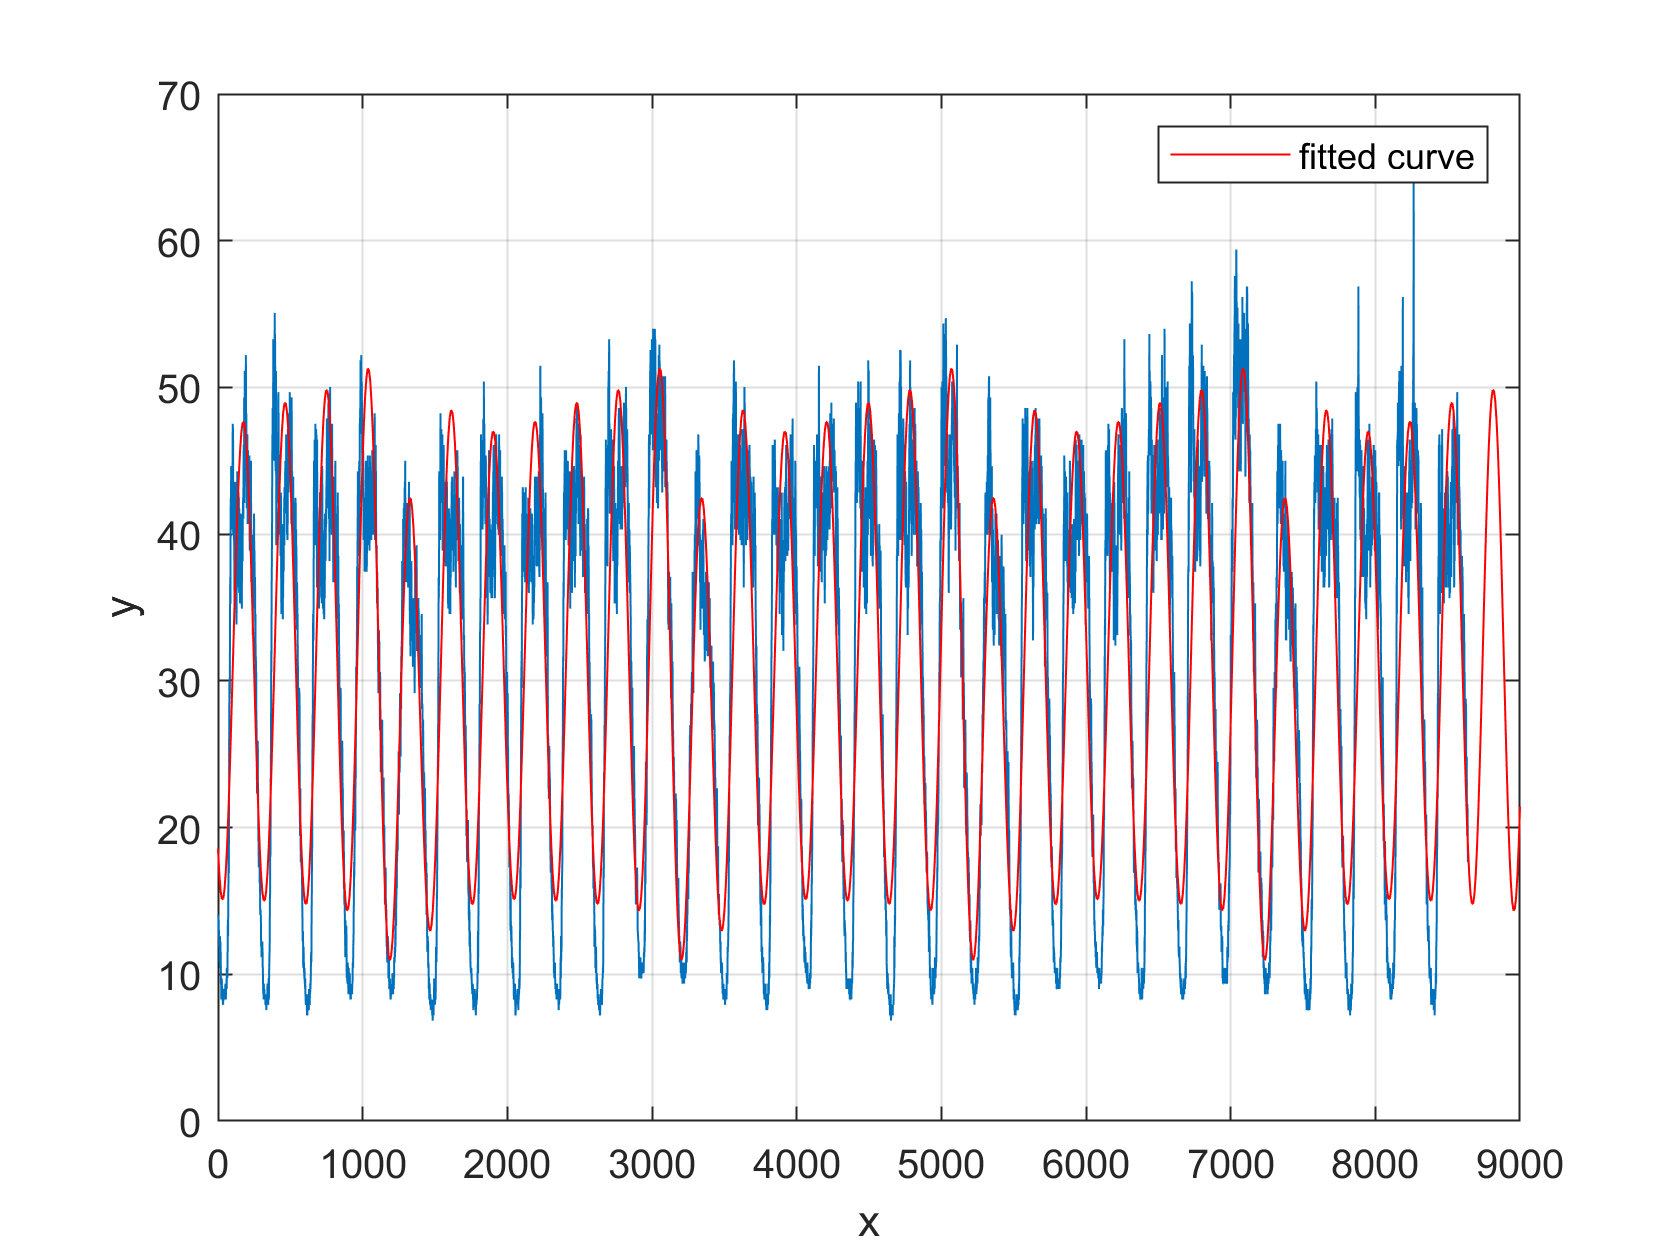

f3 = fit(KDW,FDW,'fourier8', 'StartPoint', coeffs);

figure
plot(FDW)
hold all
plot(f3)
grid on

### **Solving this for more Fourier coefficients**


$$y = a_0 + \sum_{i=1}^{n} a_i \cos(iwx) + b_i \sin(iwx)$$


FourierTerms = 100;
w = 2 * pi/(288*7);
A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];

% Solve the least squares equations "\"
rcoef = A1\FDW

rcoef =    30.9929
    0.2873
    0.5082
   -1.2629
    0.9692
   -0.0456
    0.1837
  -13.2386
    0.5859
    0.1193


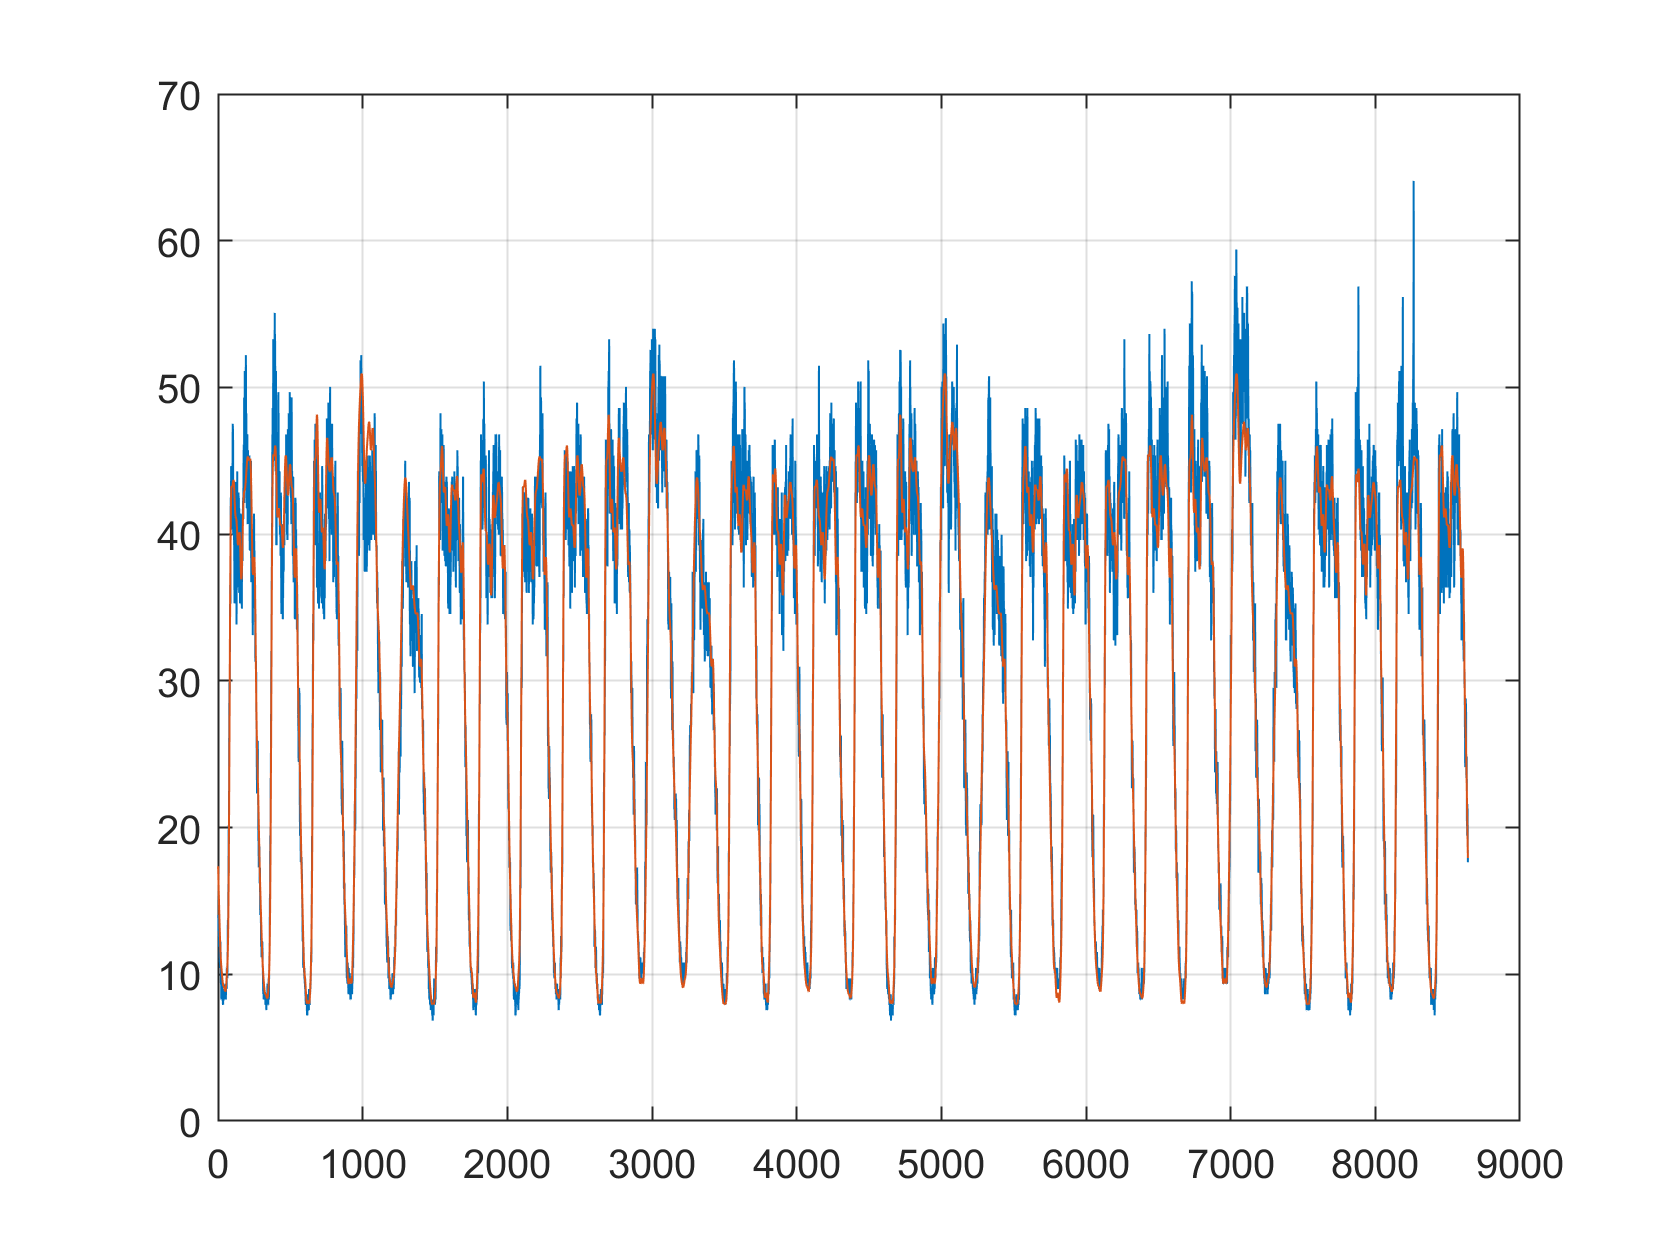

% Compute the Fourier Series
f4 = A1*rcoef;

figure
plot(FDW)
hold on
plot(f4)
grid on

### **Does this forecast the future?**

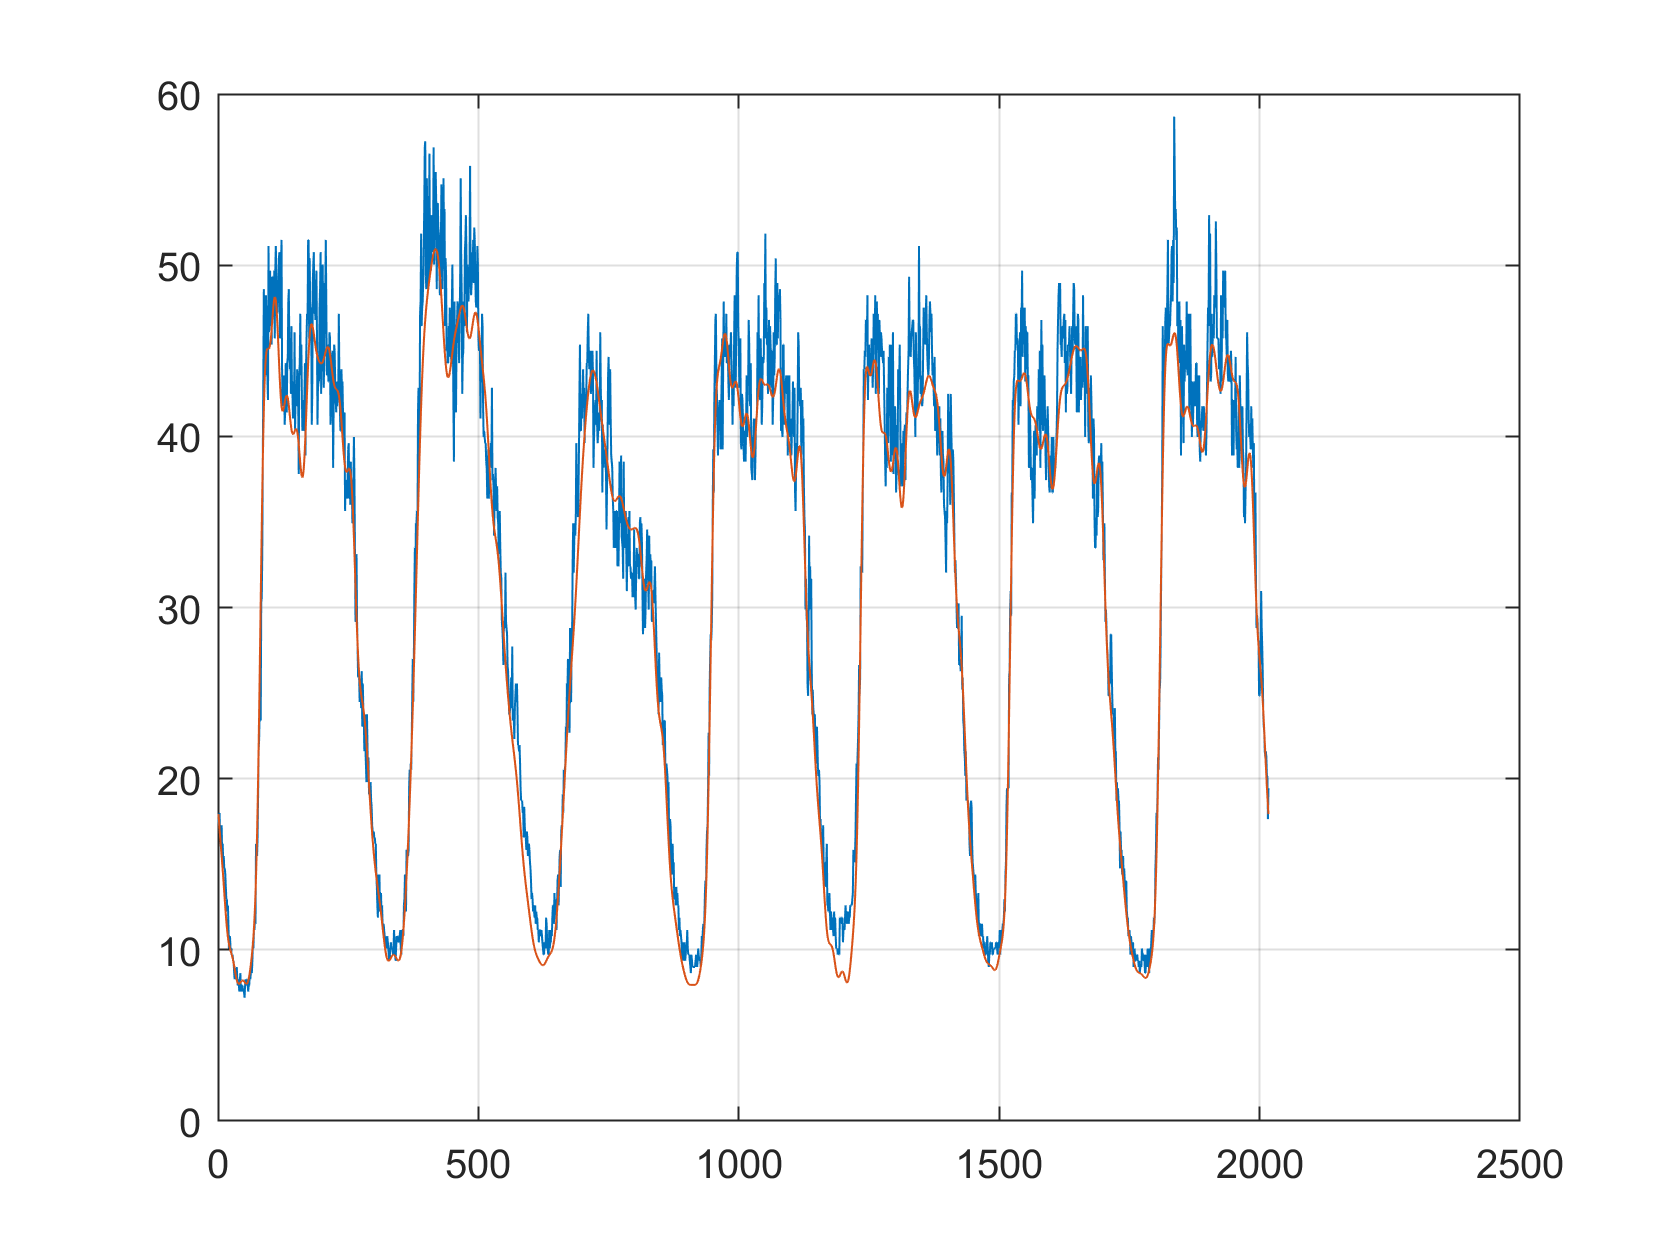

KDW = (DW:(DW+288*7))'; % next week, which we haven't learned

% compute the fourier values
A2 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
% forecast 
f5 = A2*rcoef;

figure
plot(Flow(KDW))
hold all
plot(f5)
grid on

**What is the distribution of the error?**

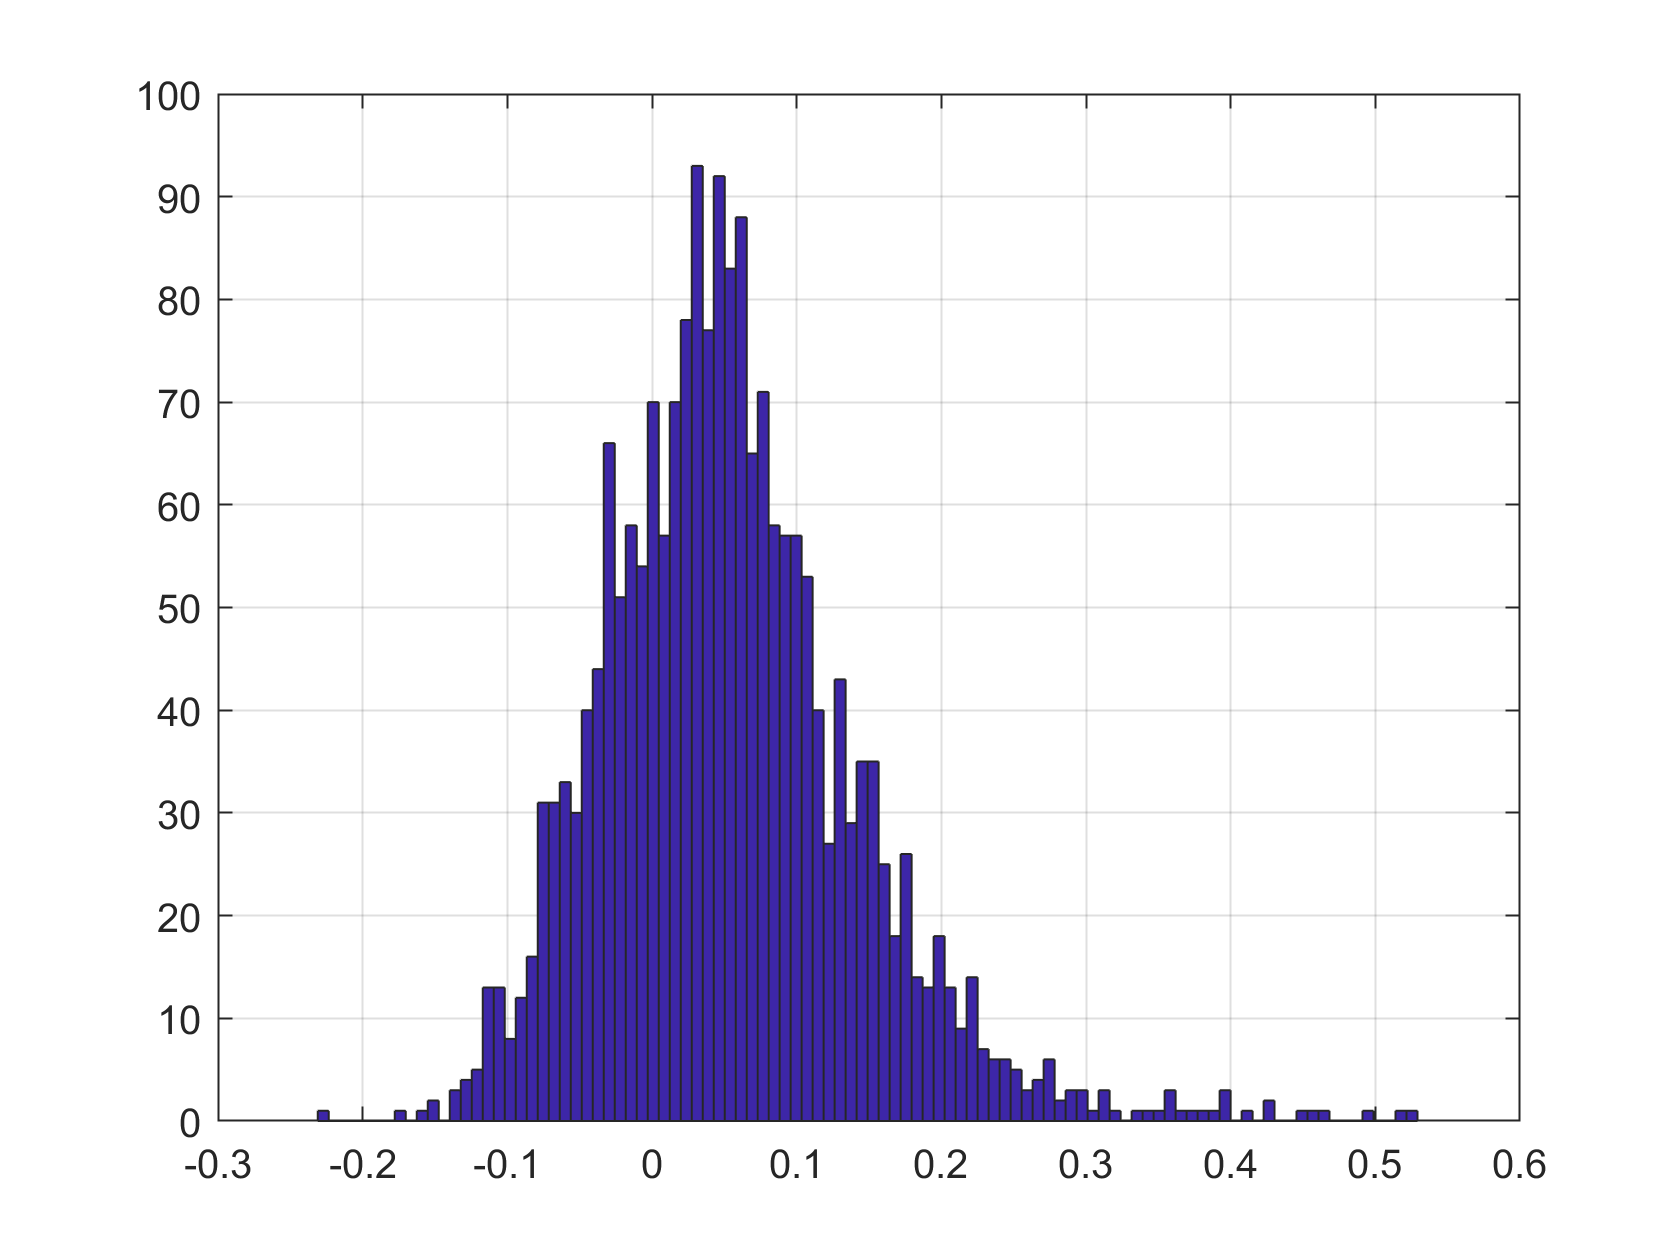

figure 
e = Flow(KDW)./f5 - 1 ;
hist(e,100); 
grid on

### **Is it a Normal Distrbution?**

We can try a "normality test", such as the Lilliefors test, if h = 1 then reject the null hypothesis, i.e., not from a normal distribution.

[h1, p1] = lillietest(e)

h1 = 1

p1 = 1.0000e-03

Another way is to check the QQ plots

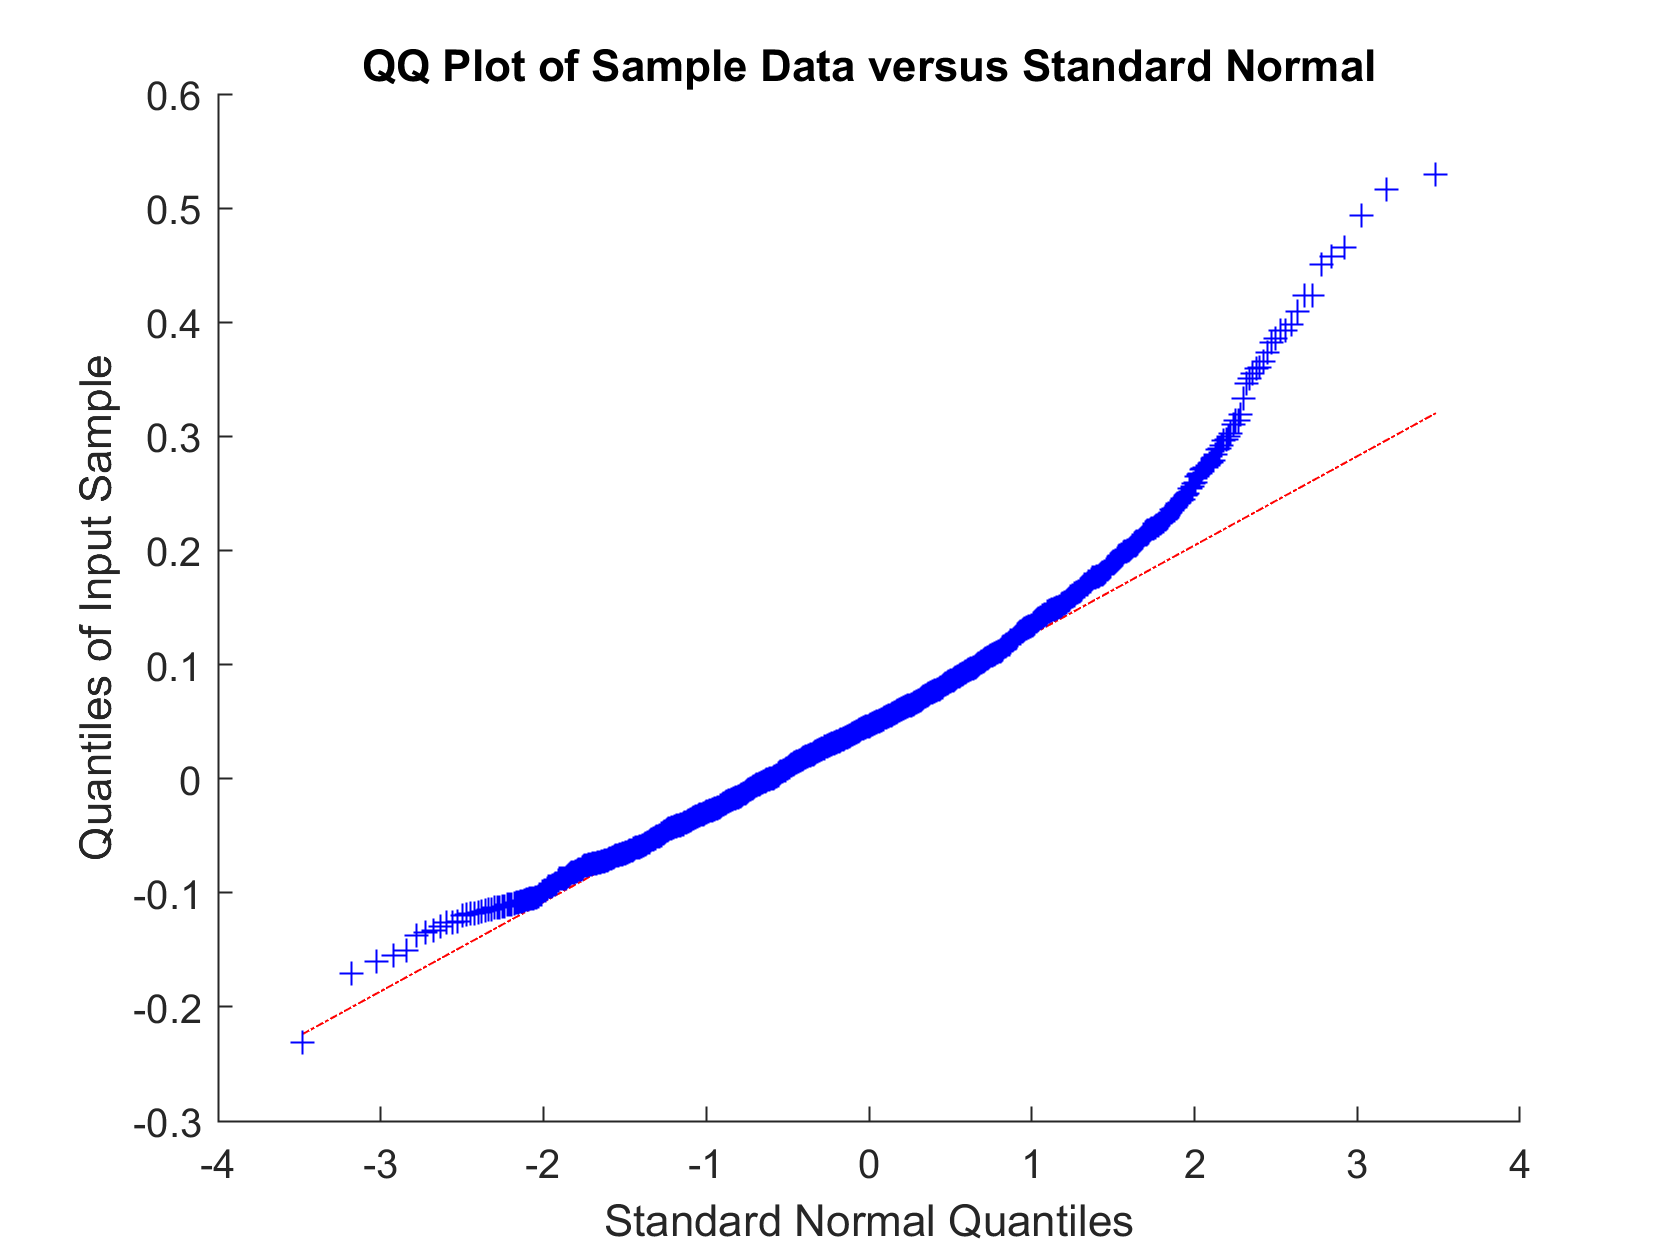

qqplot(e) 

We can make a Normal distribution

pd = fitdist(e,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0.0540531   [0.0501776, 0.0579286]
    sigma = 0.0887506   [0.086094, 0.0915777]


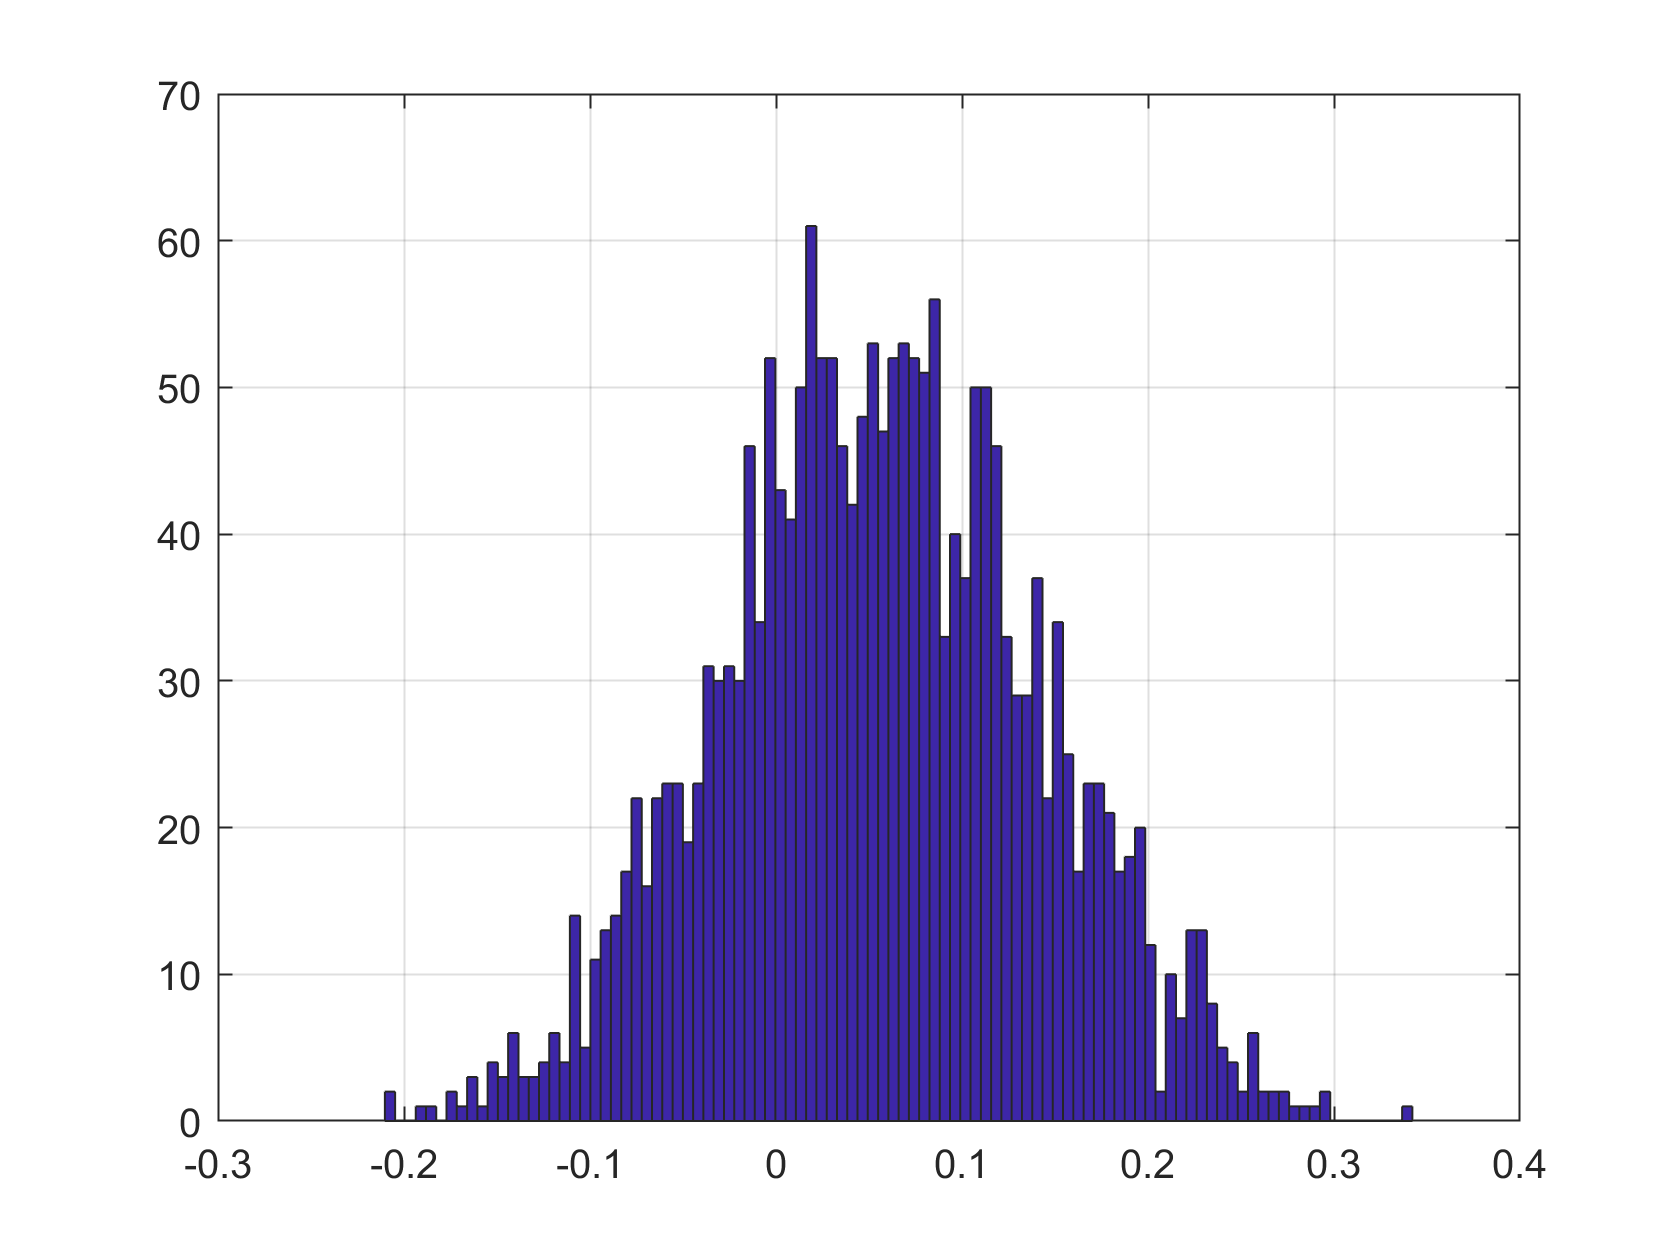

hist(pd.mu + randn(length(e),1)*pd.sigma,100)
grid on

This is not very similar. How about the Logistic distribution?

pdlog = fitdist(e,'Logistic')

pdlog =   LogisticDistribution

  Logistic distribution
       mu = 0.0489449   [0.0453131, 0.0525766]
    sigma = 0.0481055   [0.0463804, 0.0498948]


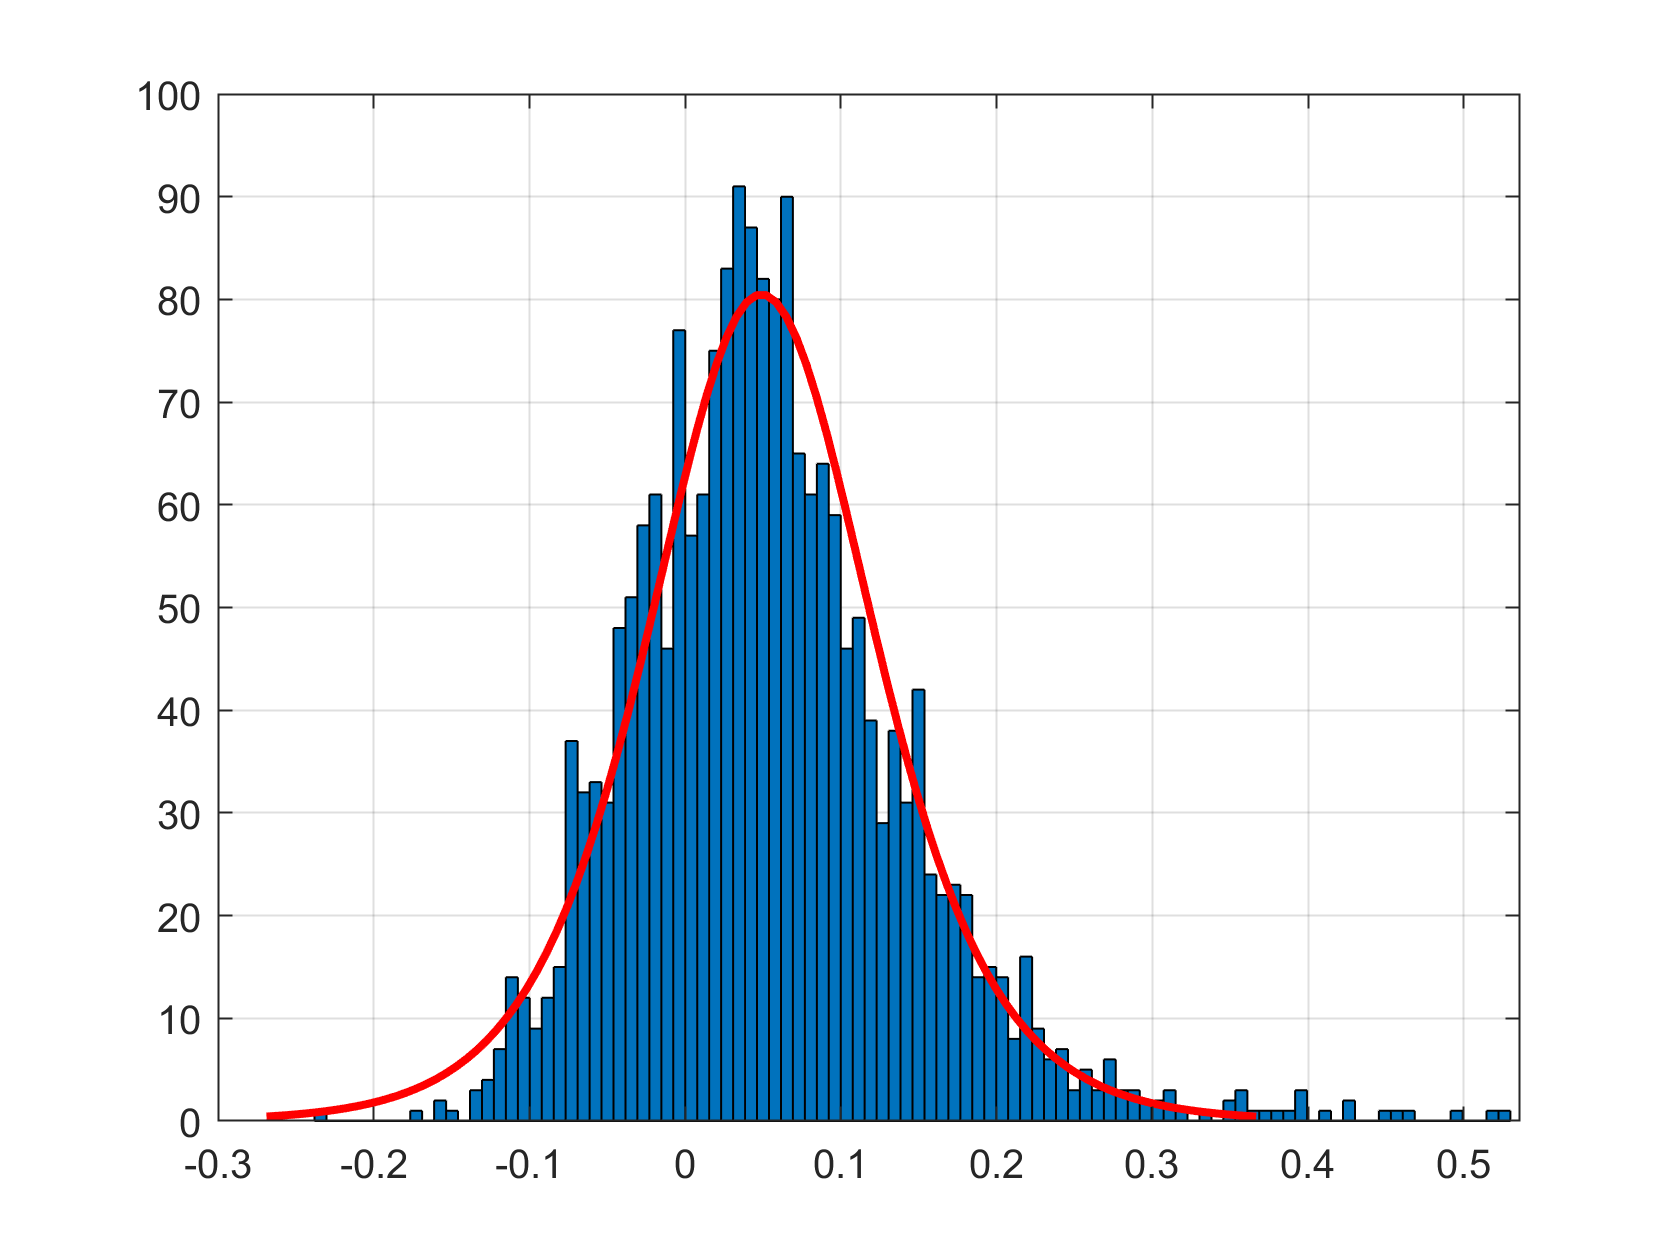

histfit(e,100,'logistic')
grid on

Multiplicaltive model


$$y(k) = r(k) s(k) (1+ \eta(k))$$


where

$r(k)$ is the annual seasonality 

$s(k)$ is the weekly periodicity

$\eta(k)$ is the noise, according to some distribution

Reconstructing the signal

## **Leakage Detection**

Let's create a dataset with a leakage

Dsim = 100 % Simulation days

Dsim = 100

K = (1:288*Dsim)'; % time steps of simulation

% compute the fourier values
A6 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))']

A6 =     1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9998    0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9990    0.9989    0.9988    0.9986    0.9984    0.9982    0.9981    0.9979    0.9977    0.9974    0.9972    0.9970    0.9967    0.9965    0.9962    0.9959    0.9956    0.9953    0.9950    0.9947    0.9944    0.9941    0.9937    0.9934    0.9930    0.9926    0.9922    0.9918    0.9914    0.9910    0.9906    0.9902    0.9897    0.9893    0.9888    0.9884
    1.0000    1.0000    0.9999    0.9998    0.9997    0.9995    0.9993    0.9990    0.9988    0.9984    0.9981    0.9977    0.9972    0.9967    0.9962    0.9956    0.9950    0.9944    0.9937    0.9930    0.9922    0.9914    0.9906    0.9897    0.9888    0.9879    0.9869    0.9859    0.9848    0.9837    0.9826    0.9814    0.9802    0.9789    0.9776    0.9763    0.9749    0.9735    0.9721    0.9706    0.9691    0.9675    0.9659    0.9643    0.9626    0.9609    0.9592    0.9574    0.9556    

% create weekly periodicity 
s = A6*rcoef

s =    17.3633
   16.8858
   16.4417
   16.0239
   15.6254
   15.2398
   14.8619
   14.4882
   14.1174
   13.7497


% create noise
eta = random(pdlog,length(K),1);
y = s.*(1+eta)

y =    15.5103
   18.9710
   17.7196
   13.6747
   15.6563
   15.2404
   12.6250
   15.1966
   15.2520
   15.5169


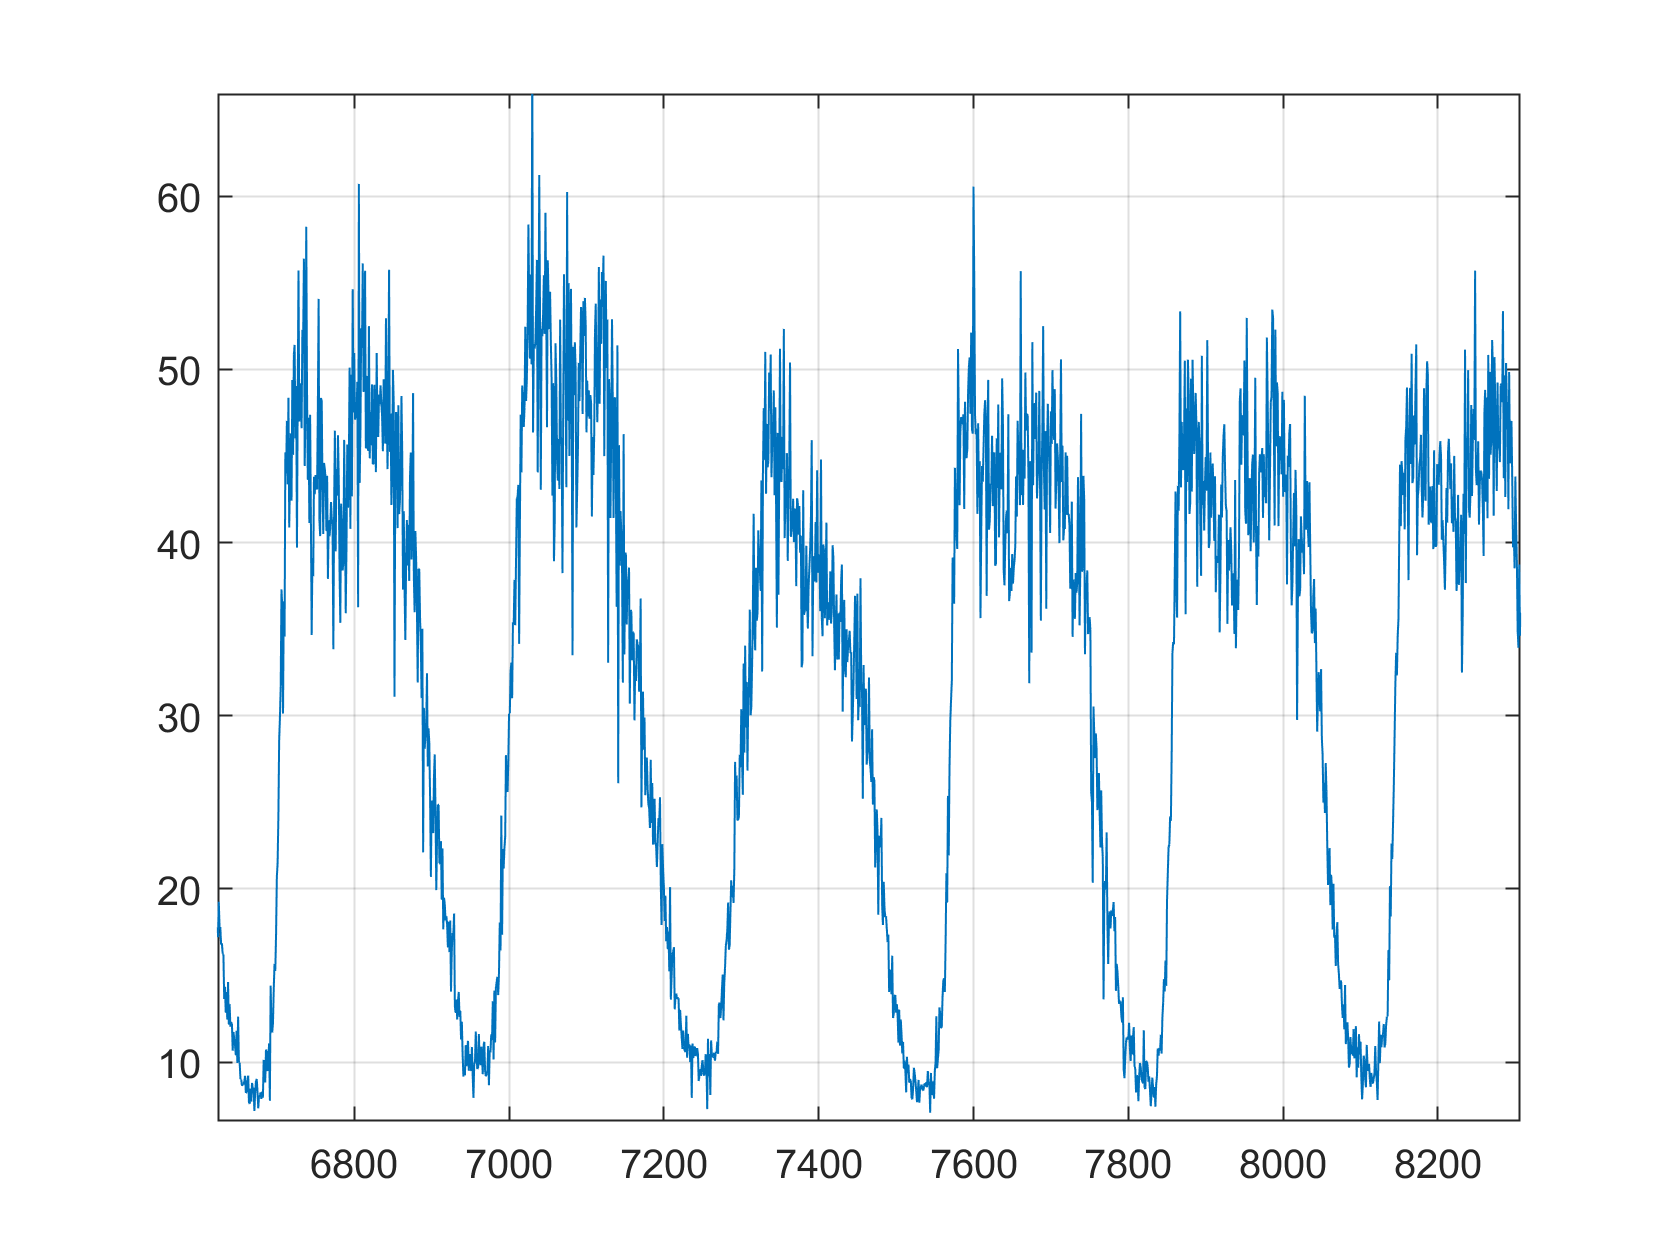


figure
plot(y)
grid on
xlim([6624 8306])
ylim([6.6 65.9])

**Simulate a leakage event**

leakSize = 5 % m3/h

leakSize = 5

leakDay = 60.5

leakDay = 60.5000

T0 = leakDay * 288;
T1 = T0 + 288*7;
phi = zeros(length(K),1);
phi(T0:T1) = leakSize;
y2 = y + phi

y2 =    15.5103
   18.9710
   17.7196
   13.6747
   15.6563
   15.2404
   12.6250
   15.1966
   15.2520
   15.5169


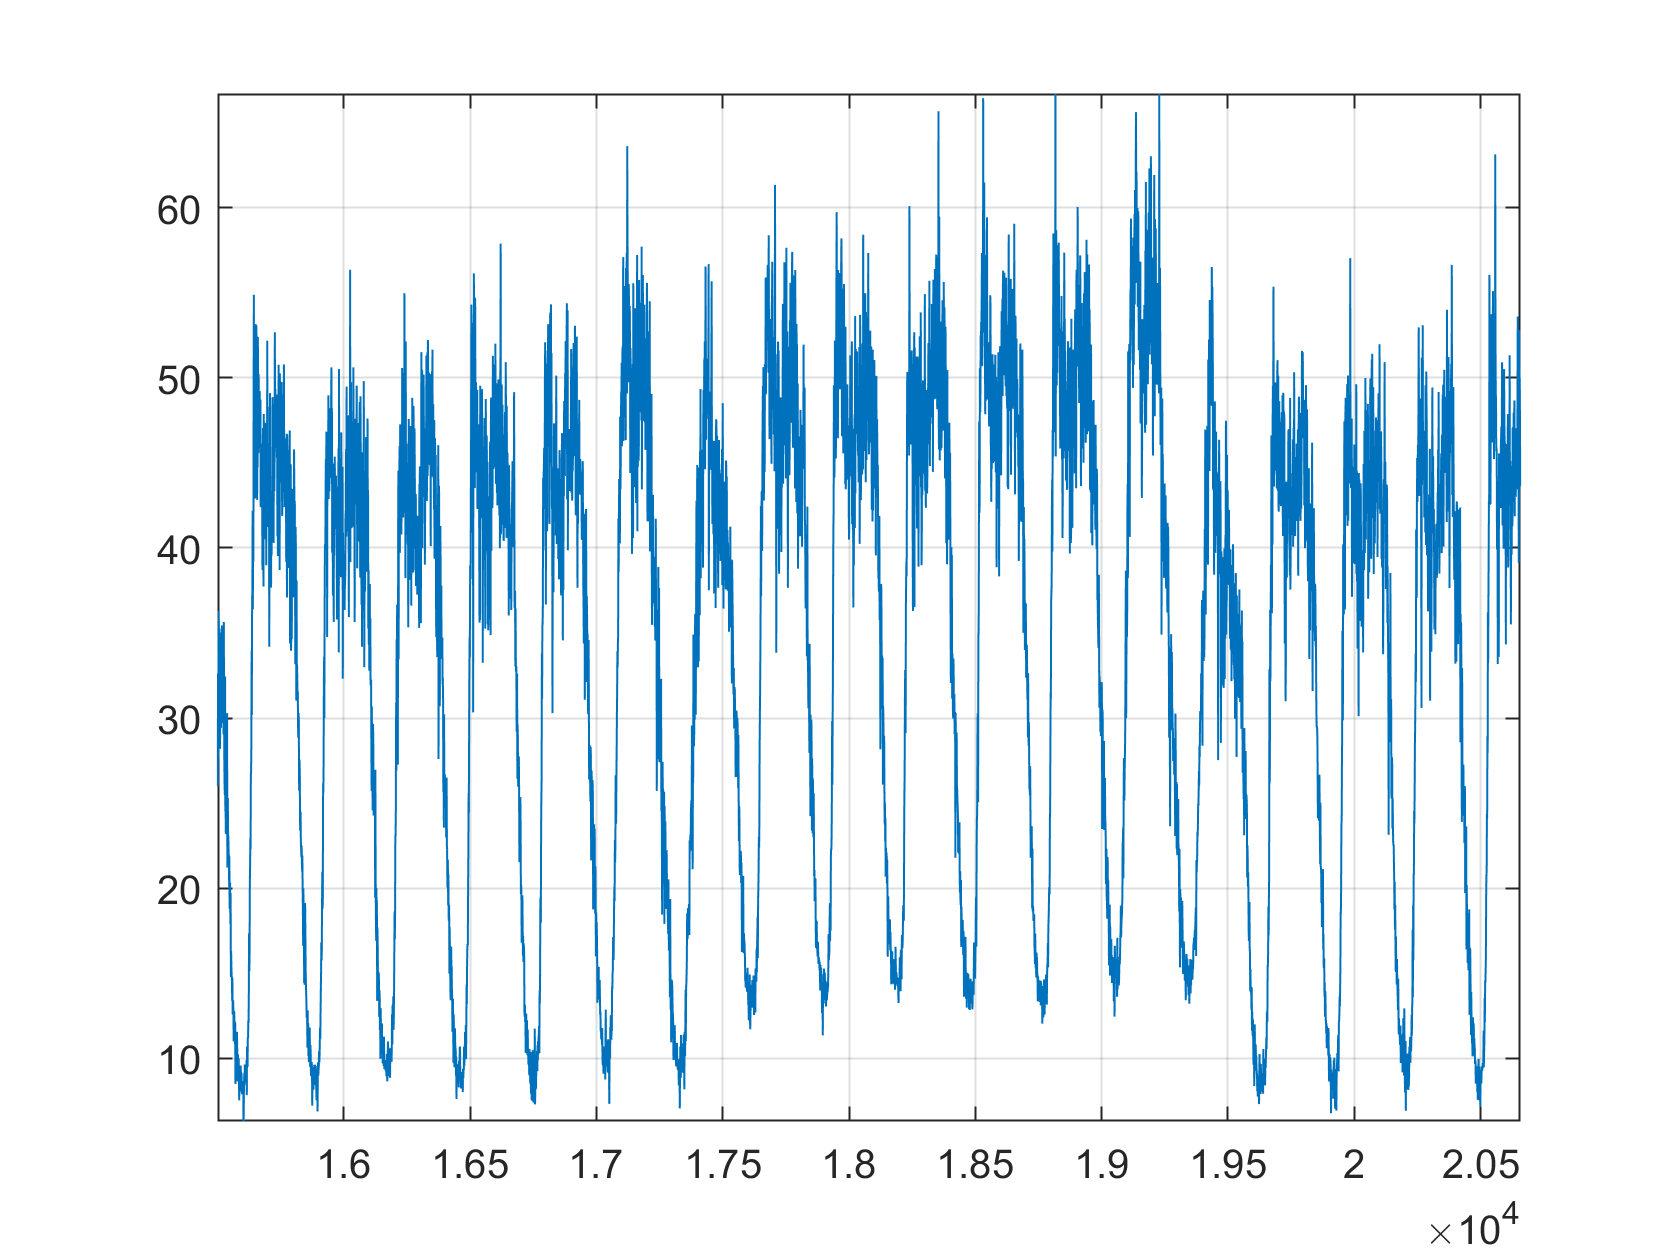


figure
plot(y2)
grid on
xlim([15502 20656])
ylim([6.3 66.7])

**Minimum Night Flow Analysis**

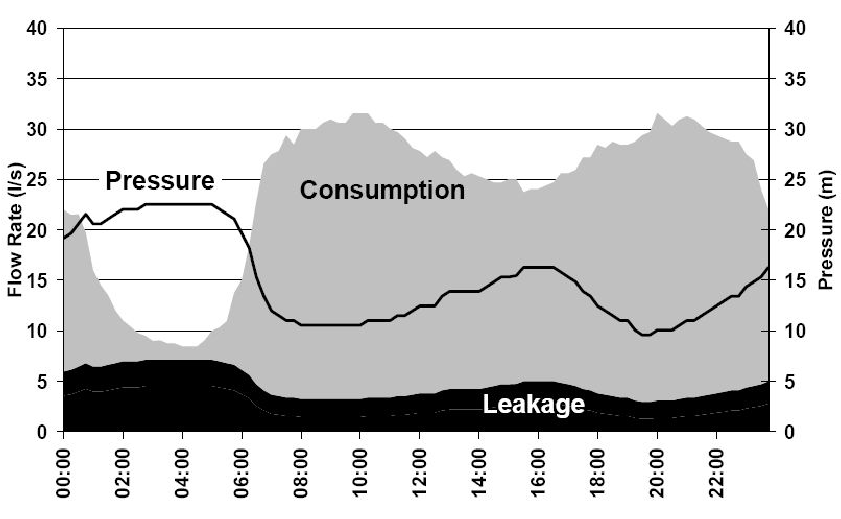

- Basic idea is that each night the uncertainty is low

- Demand is low

- Pressure is high

- Easier to detect leakages

% compute the minimum flow for each day
Y = reshape(y2,288,100)

Y =    15.5103   19.3273   19.7515   16.9357   20.5829   13.8559   17.0475   16.6015   18.7153   20.3968   20.0886   22.7185   17.4778   15.1709   18.4785   16.5868   19.3446   23.1106   19.8374   17.5544   17.5129   18.7560   15.9586   19.2628   19.3758   18.1457   16.9279   17.7164   20.2955   18.6309   18.1976   20.1758   20.7957   16.6846   19.5688   16.6471   16.2544   17.7344   17.7628   21.0457   20.2408   18.7506   19.5087   18.3931   19.1270   20.4908   18.8213   14.5233   19.1648   18.1233
   18.9710   16.2501   17.8594   20.2191   17.3751   16.4148   19.4327   23.4117   17.7381   18.4248   18.6137   18.2667   17.4785   19.3125   18.5944   17.4893   16.0692   20.1376   19.4943   14.4221   20.9966   18.1288   16.6922   17.7971   22.3396   19.6081   17.3610   18.7604   17.1786   19.3873   17.7516   20.1698   18.0789   15.2064   20.4338   16.7530   16.5684   17.0216   19.4026   18.1645   18.4364   17.7323   20.1389   17.4227   18.8140   20.7734   19.4890   16.1876   20.6744   17

MF = min(Y)

MF =     8.1871    7.7801    7.0516    7.7658    8.6706    6.5111    7.9074    7.1568    7.0590    7.0224    7.7722    6.5856    6.3599    6.9093    8.3898    7.7804    7.6224    8.3939    7.8254    6.4301    7.8072    8.0505    7.5254    7.1817    7.9378    7.2875    7.0791    7.4257    7.8132    7.2472    6.9468    8.4044    8.5311    5.5655    7.2979    7.1546    7.0596    6.0903    8.0376    8.0558    6.3169    7.8632    7.7299    8.2297    7.1844    8.1477    7.9281    7.5808    7.9397    7.4412


grid on

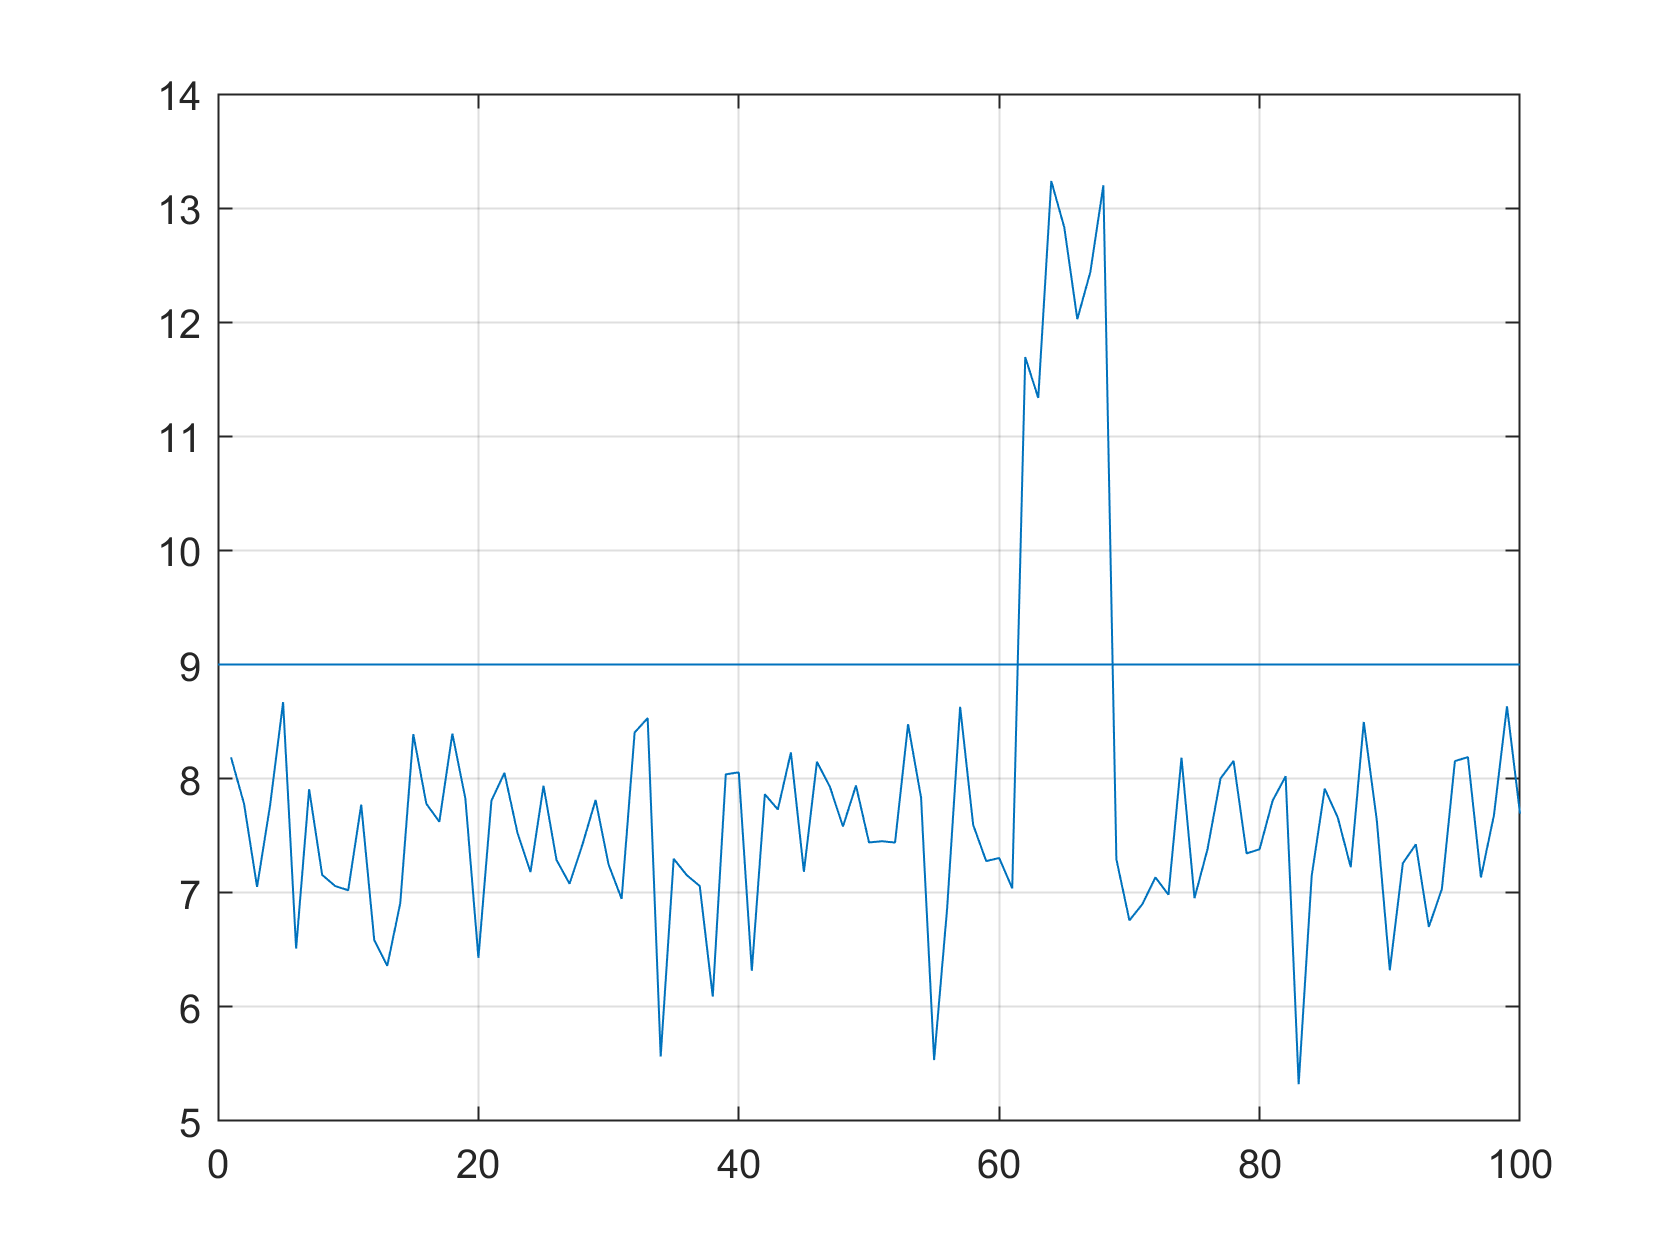

plot(MF)
grid on
line([100,0],[9,9])

**Detecting changes**

- Change detection algorithms

- Limit checking, change in mean

- Cumulative Sum (CUSUM)

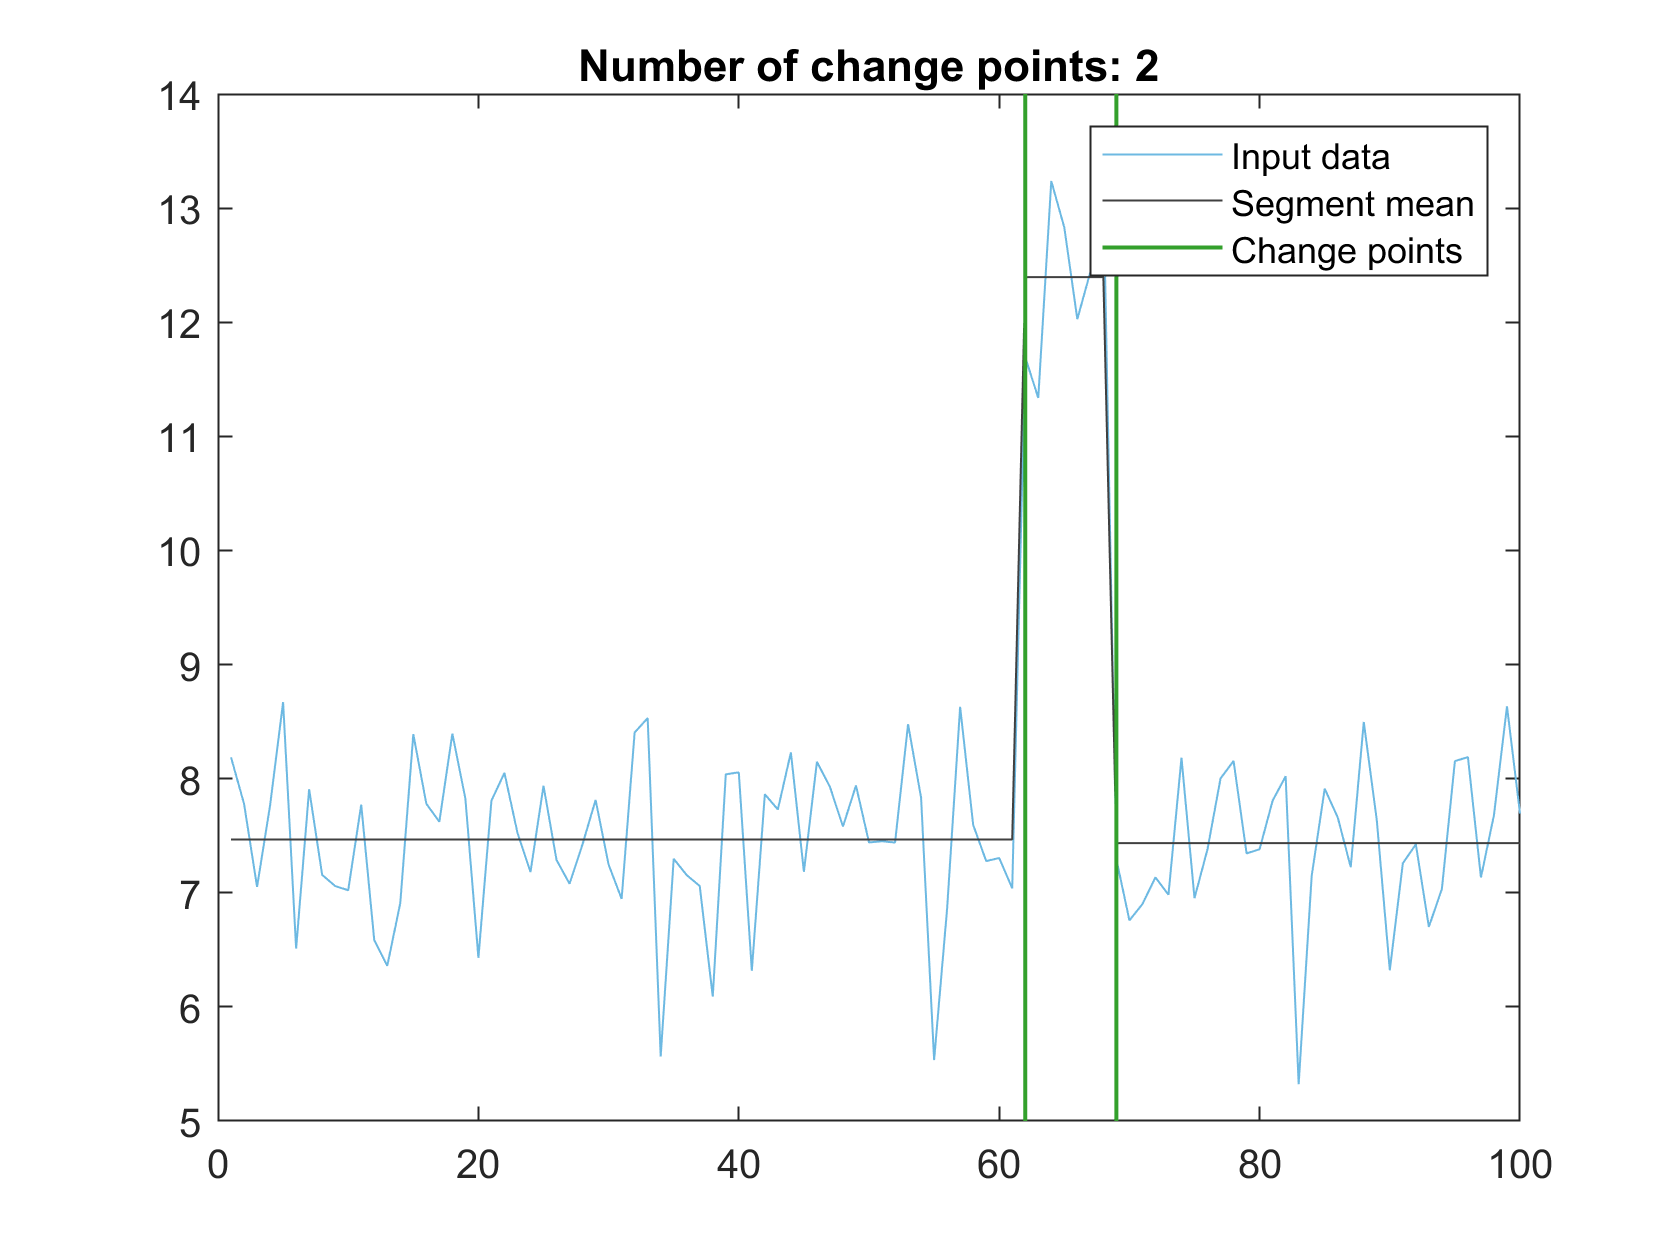

% Find change points
[changeIndices,segmentMean] = ischange(MF,'Threshold',3);

% Visualize results
clf
plot(MF,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')

% Plot change points
x = repelem(find(changeIndices),3);
y3 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y3,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

clear segmentMean x y3


Limit checking, the most simple detection algorithm

threshold = 9

threshold = 9

alert = MF > threshold

alert = 1×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


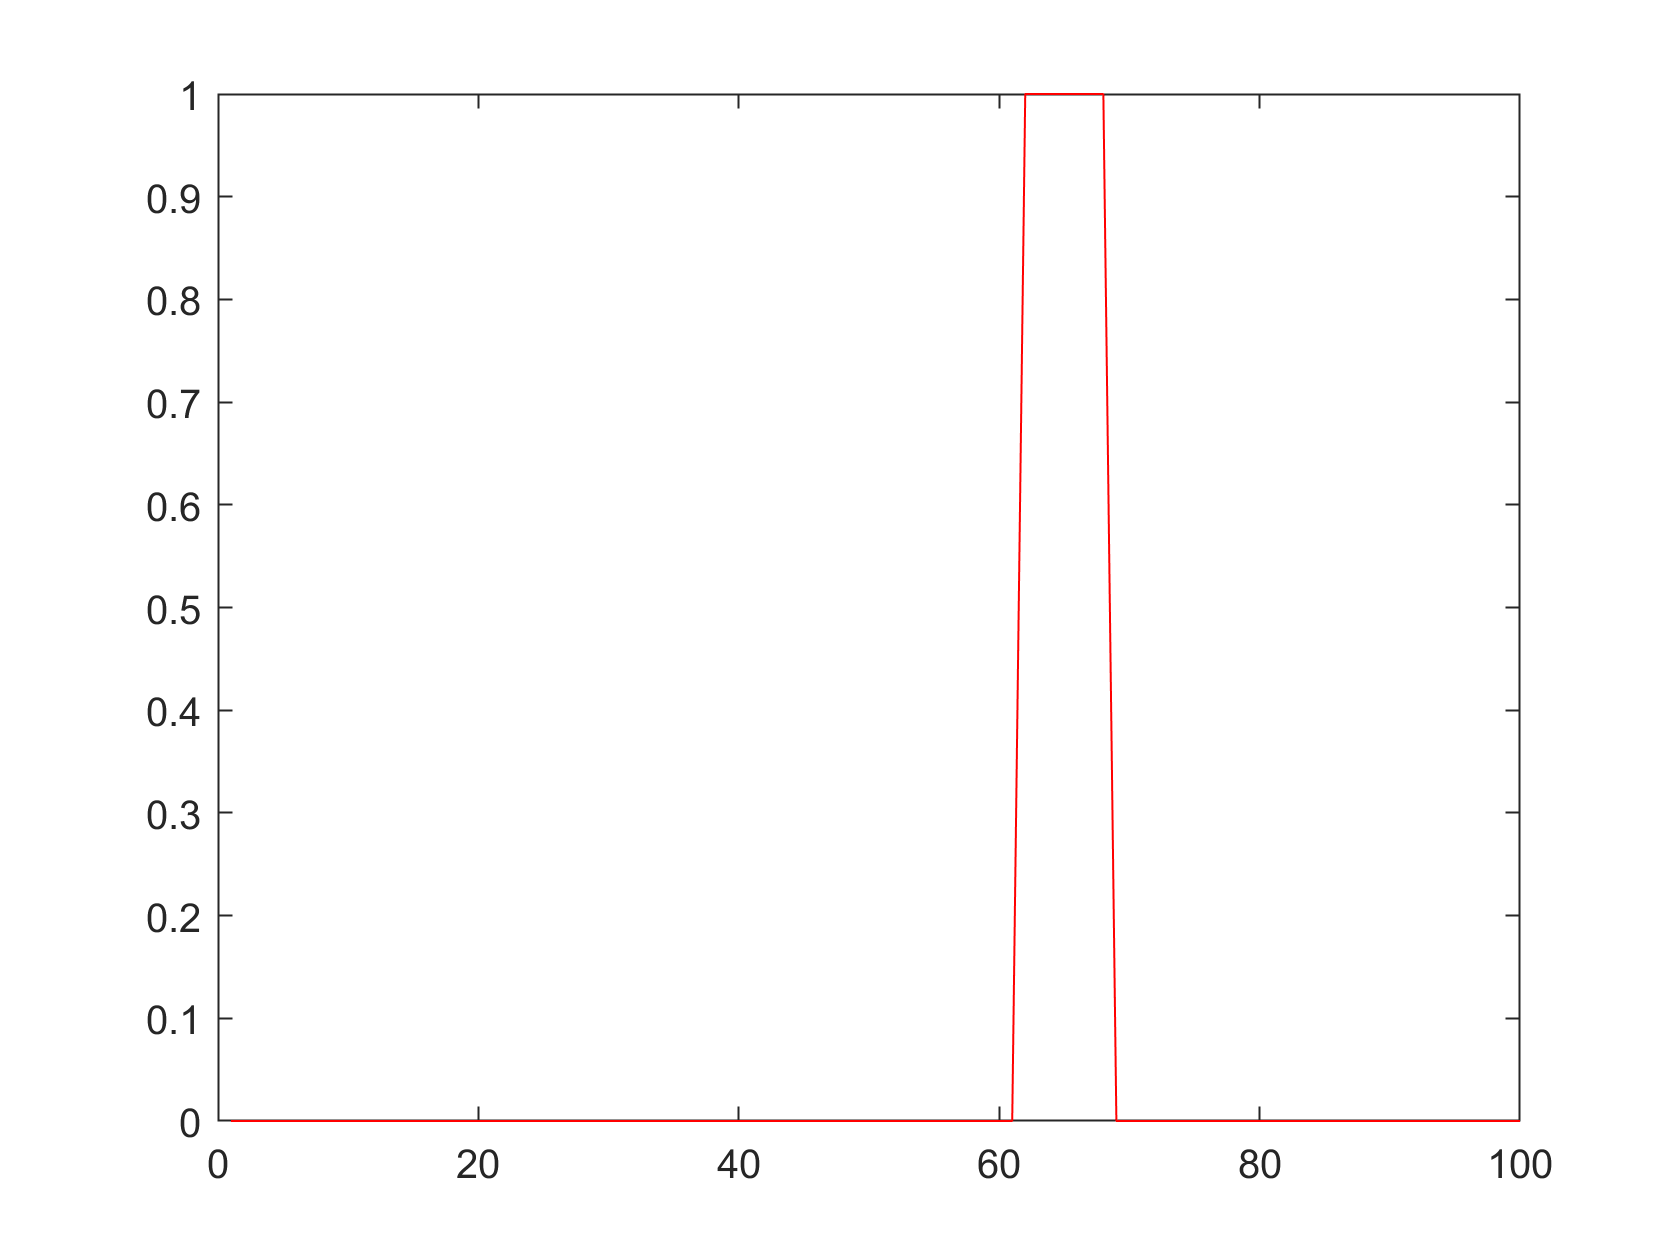


figure
plot(alert, 'r-')

A different approach would be to take a window of minimum (night) flows, and compare them with the new minimum flow. If it exceeds a precalculated distance, the issue an alert.

## **Regulating Chlorine in Drinking Water Networks**

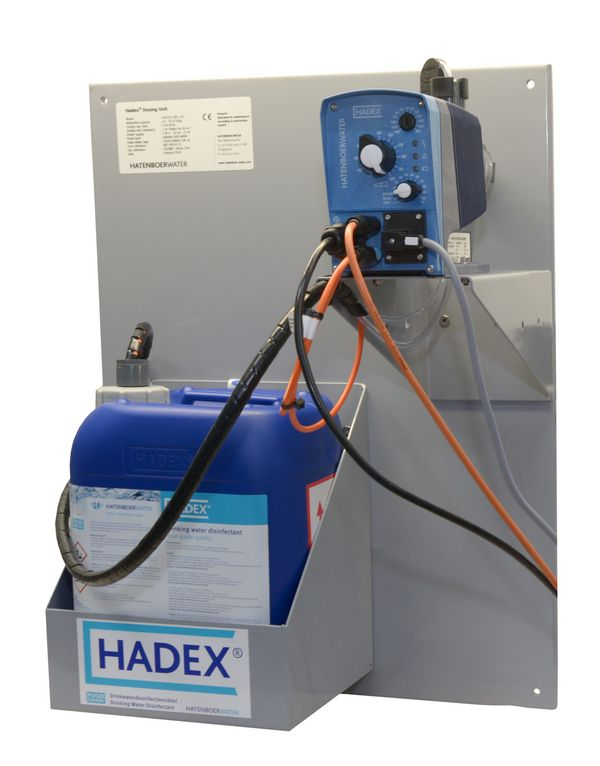

- Chlorine can be injected in one or more locations in a water distribution network

- Typically an actuation sets the chlorine concentration to a specific setpoint

- For instance, in Cyprus, some utilities have 0.4 mg/L chlorine in their inputs 

**Problem formulation**

Find a control input $U(k)$ tha minimizes a cost function over a prediction horizon, subject to constraints.

Assuming linear chlorine dynamics, the Input/Output relation of chlorine is given by


$$y(k) = \sum_{i=0}^{k-1} h_i u(i) = H(k)U(k) + f(k)$$


$H(k)$ is the dynamic matrix which corresponds to the discrete impulse responses.

**What happens when injection chlorine concentration is fixed?**

G = epanet('NET1CL2.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "NET1CL2.inp"...
Input File "NET1CL2.inp" loaded sucessfuly.


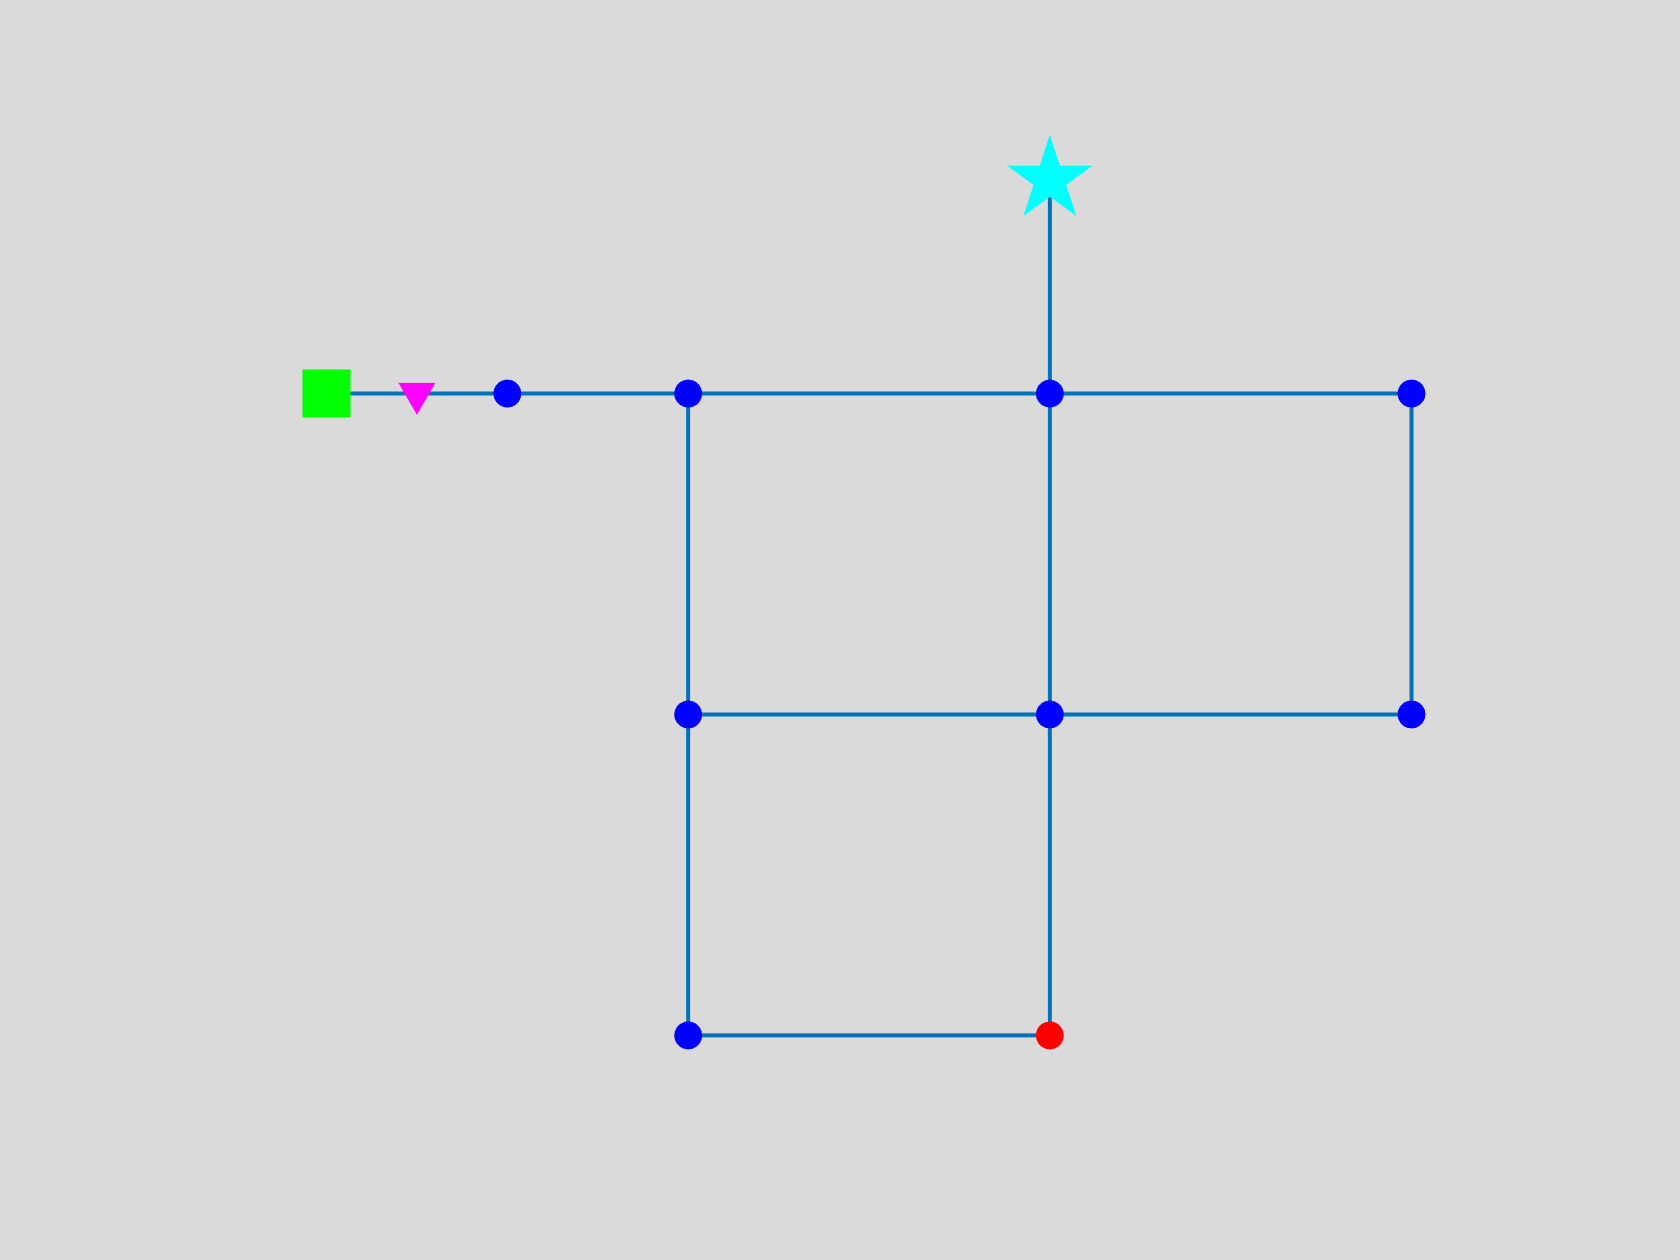

G.plot('highlightnode',{'32'});


SourceID = '9'; % Source node id
SimDays = 2;
SimTime = SimDays*24*3600;
G.setTimeSimulationDuration(SimTime) % Set simulation time
Nnodes = G.getNodeCount % Get the number of nodes

Nnodes = int32
11

sourceindex = G.getNodeIndex(SourceID) % Get source node's index

sourceindex = int32
10

G.setQualityType('Chlorine', 'mg/L', '') % Setup system to analyze for chlorine (in case it was not done in the input file.)

% make all initial concentrations 0 mg/L
zeroNodes=zeros(1,G.NodeCount);
G.setNodeInitialQuality(zeroNodes);

cl2_conc = 1

cl2_conc = 1

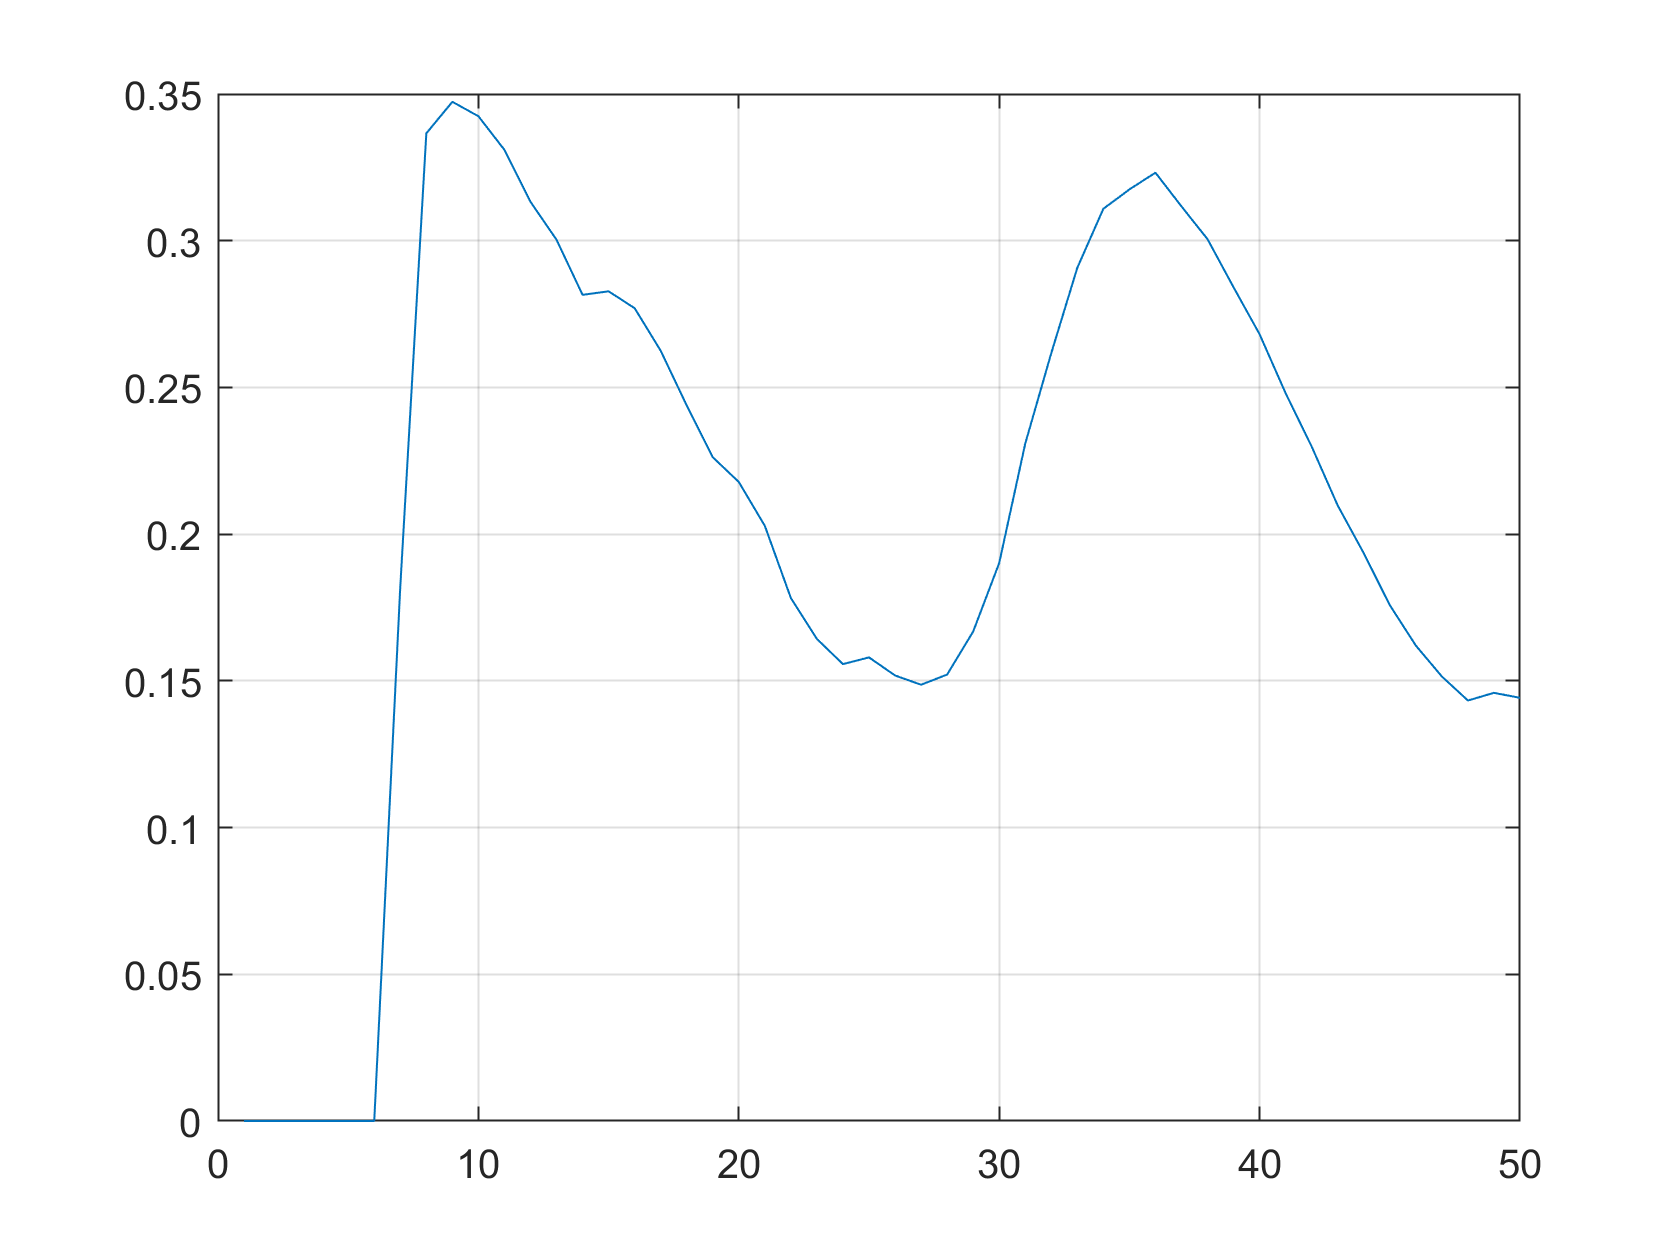


G.setNodeSourceQuality(sourceindex, cl2_conc);
Q = G.getComputedQualityTimeSeries.NodeQuality;

figure
plot(Q(:,9))
grid on


Q9 = Q(:,9)

Q9 =          0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.1821
    0.3366
    0.3473
    0.3424


**How to regulate chlorine concentration at 0.2 mg/L at Node '32'?**

G = epanet('NET1CL2.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "NET1CL2.inp"...
Input File "NET1CL2.inp" loaded sucessfuly.


G.plot('highlightnode',{'32'});


SourceID = '10'; % Source node id
SimDays = 2;
SimTime = SimDays*24*3600;
G.setTimeSimulationDuration(SimTime) % Set simulation time
Nnodes = G.getNodeCount % Get the number of nodes

Nnodes = int32
11

sourceindex = G.getNodeIndex(SourceID) % Get source node's index

sourceindex = int32
1

G.setQualityType('Chlorine', 'mg/L', '') % Setup system to analyze for chlorine (in case it was not done in the input file.)

% make all initial concentrations 0 mg/L
zeroNodes=zeros(1,G.NodeCount);
G.setNodeInitialQuality(zeroNodes);

PAT = zeros(1,24);
PAT(1) = 1;
patidx = G.addPattern('CL2PAT',PAT)

patidx = int32
2

G.setNodeSourceType(sourceindex, 'SETPOINT');
G.setNodeSourcePatternIndex(sourceindex, patidx)
G.setNodeSourceQuality(sourceindex, 1)
Q = G.getComputedQualityTimeSeries.NodeQuality

Q =          0         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000    0.8650    0.7871    0.0000    0.0249    0.0000    0.0000         0    0.0000         0    0.0120
         0    0.8628    0.7844    0.0000    0.7369    0.0000    0.0000         0    0.0000         0    0.0787
         0         0    0.0556    0.0000    0.7361    0.0000    0.0000    0.5446    0.0000         0    0.1324
         0         0         0    0.5145         0    0.4078    0.0000    0.5547    0.0000         0    0.1220
         0         0         0    0.5326         0    0.1068    0.0000         0    0.1821         0    0.1124
         0         0         0         0         0    0.0426    0.0000         0    0.3170         0    0.1063
         0         0         0         0         0    0.0389    0.0000         0    0.0783         0    0.10

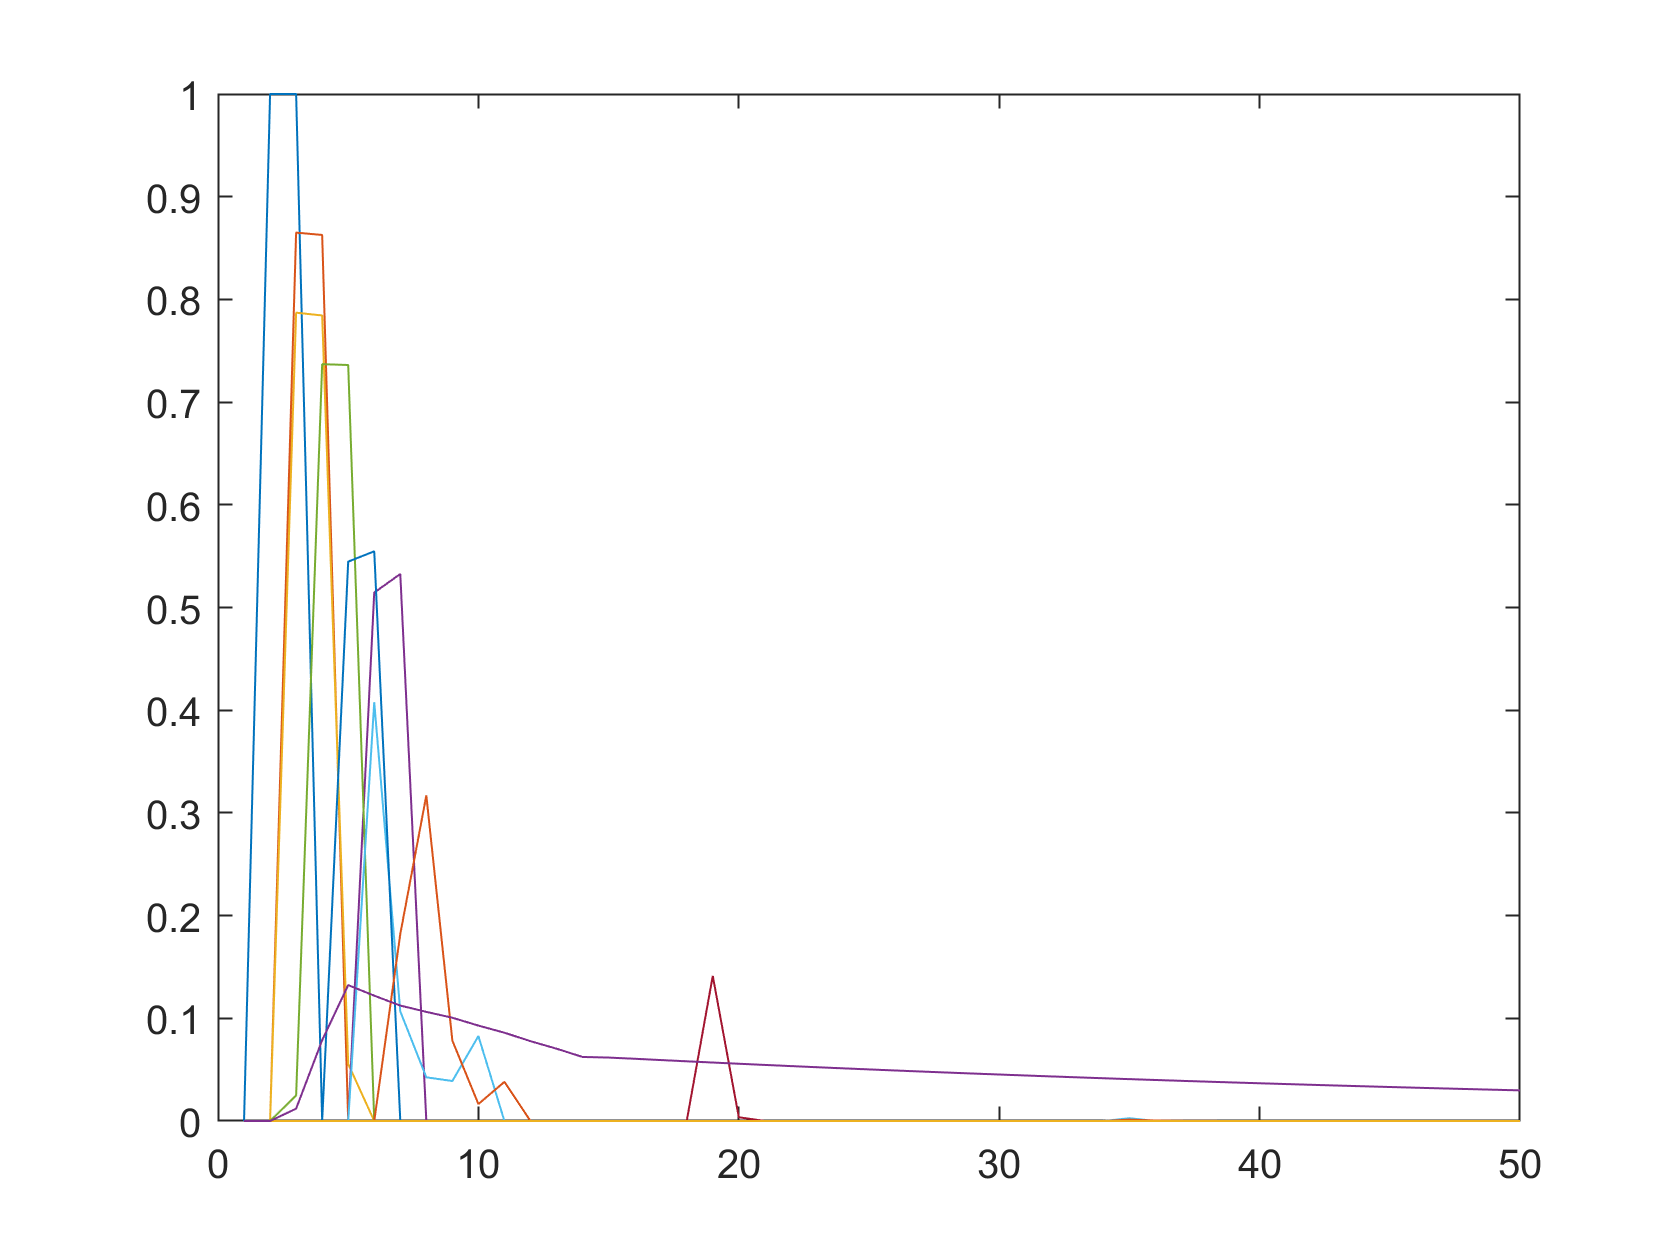

figure
plot(Q)

**Create the dynamic matrix to regulate node '32' (index 9)**

H = [];
m = 24; % forecast for a day
for i = 1:m
    PAT = zeros(1,m);
    PAT(i) = 1;
    patidx = G.addPattern('CL2PAT',PAT); % create the impulse responses
    Q = G.getComputedQualityTimeSeries.NodeQuality;
    H(:,i) = Q(:,9);
end
H

H =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000         0         0  

**Validate the Input/Output Model**

% input function
U = ones(m,1)

U =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



% output
Y1 = H*U

Y1 =          0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.1821
    0.3364
    0.3485
    0.3402


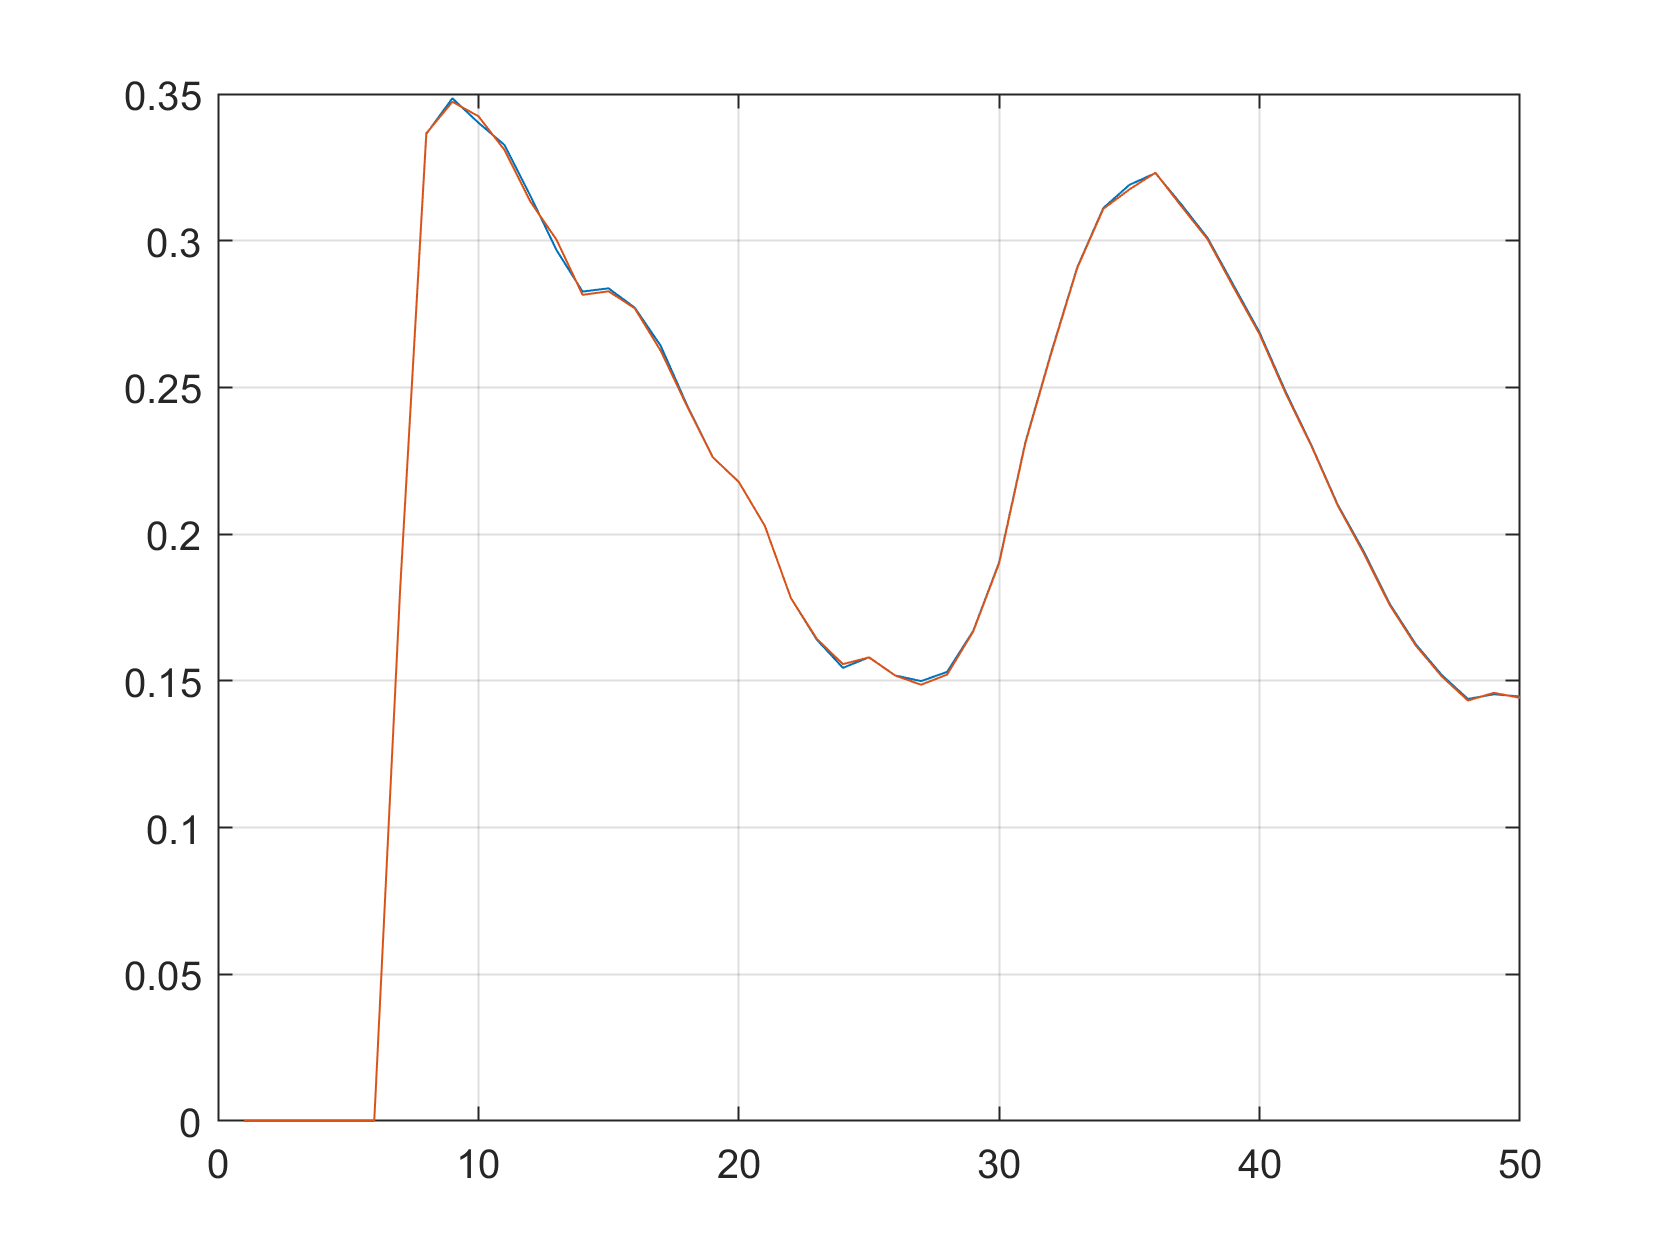


figure
plot(Y1)
hold all
plot(Q9)
grid on

**Can we make this output follow the reference signal 0.2 mg/L?**

w = zeros(50,1)

w =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


w(8:50) = 0.2 % allow dead period in the beginning

w =          0
         0
         0
         0
         0
         0
         0
    0.2000
    0.2000
    0.2000



%let's try the least squares solution
Uls = H\w

Uls =     0.4442
    0.6182
    0.6182
    0.7240
    0.8324
    1.1374
    1.3371
    1.3023
    1.1673
    0.9952


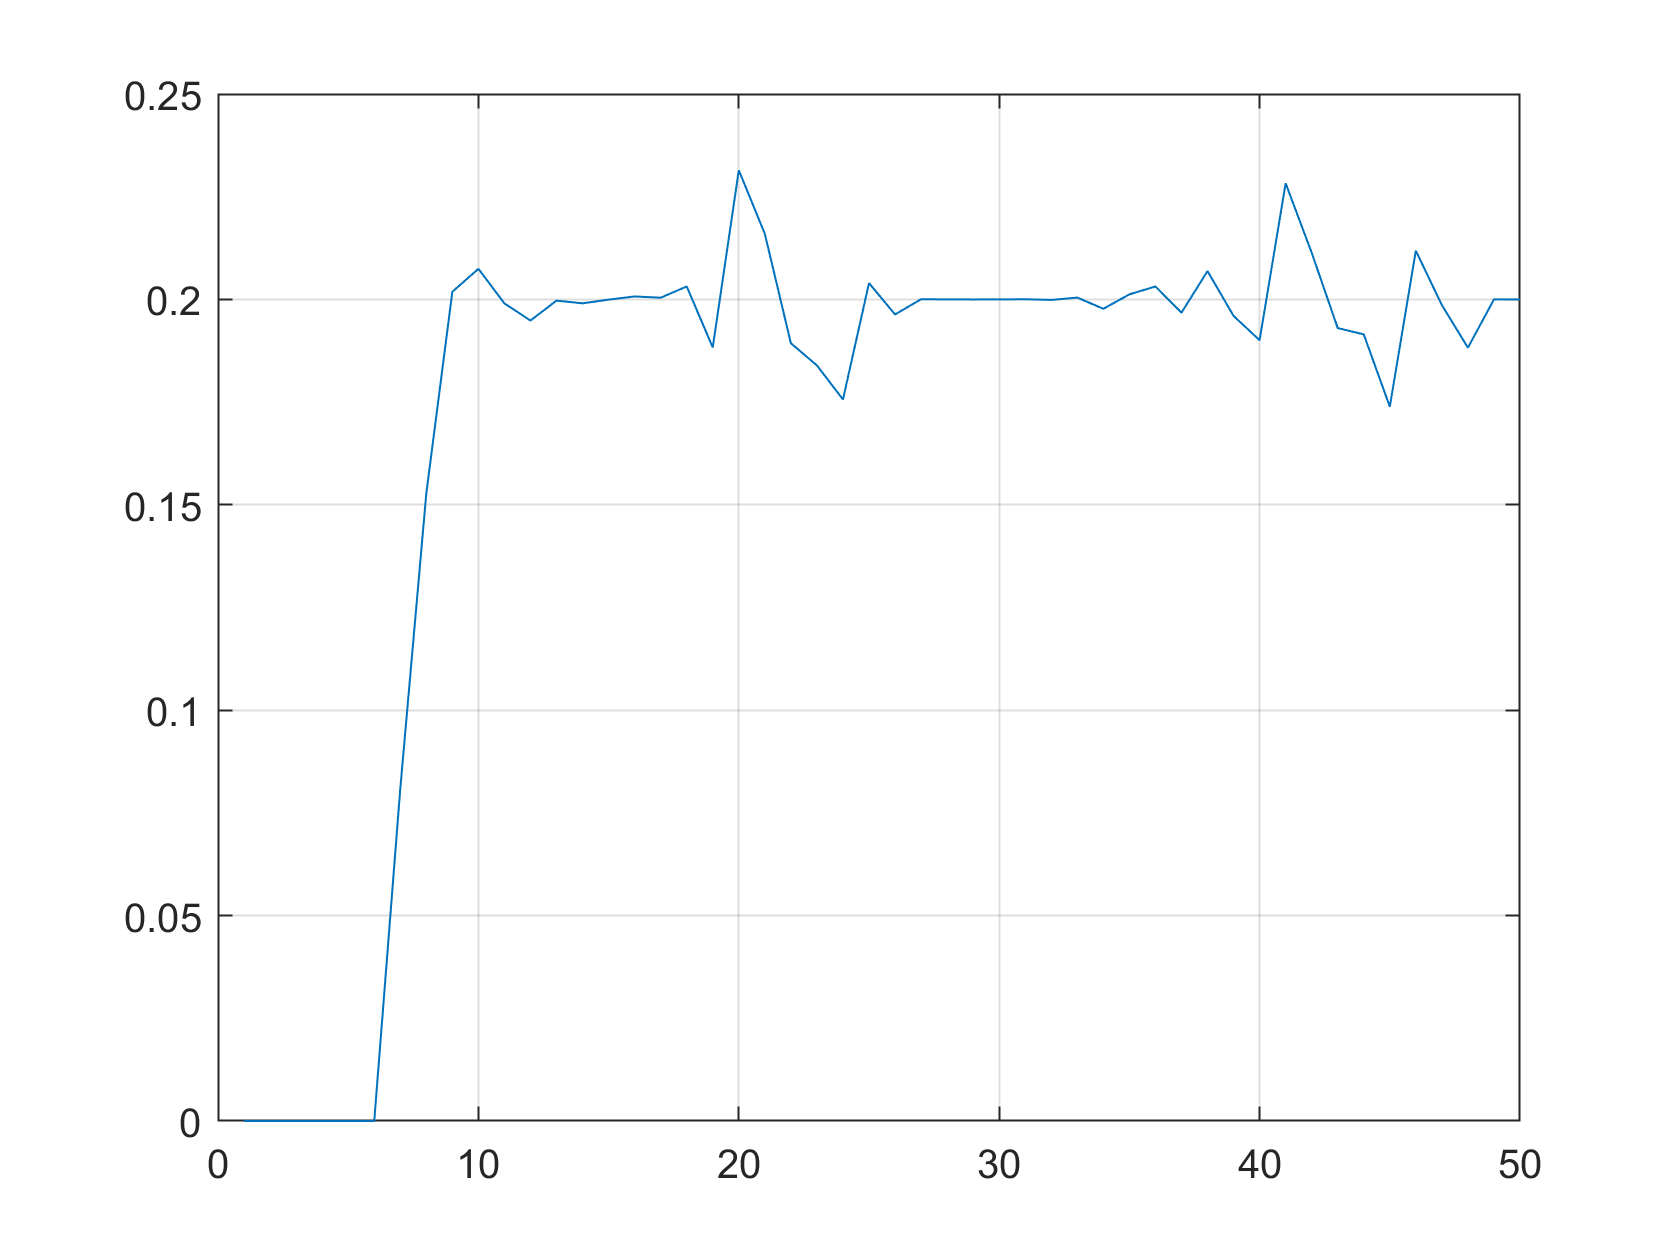


figure
plot(H*Uls)
grid on

**Looks good! But you need to be careful!**

max(Uls)

ans = 1.4118

min(Uls)

ans = -795.2792

Uls(20) % a nonsense value

ans = -795.2792


Uls(20) = 0 % removing it does not affect the solution

Uls =     0.4442
    0.6182
    0.6182
    0.7240
    0.8324
    1.1374
    1.3371
    1.3023
    1.1673
    0.9952


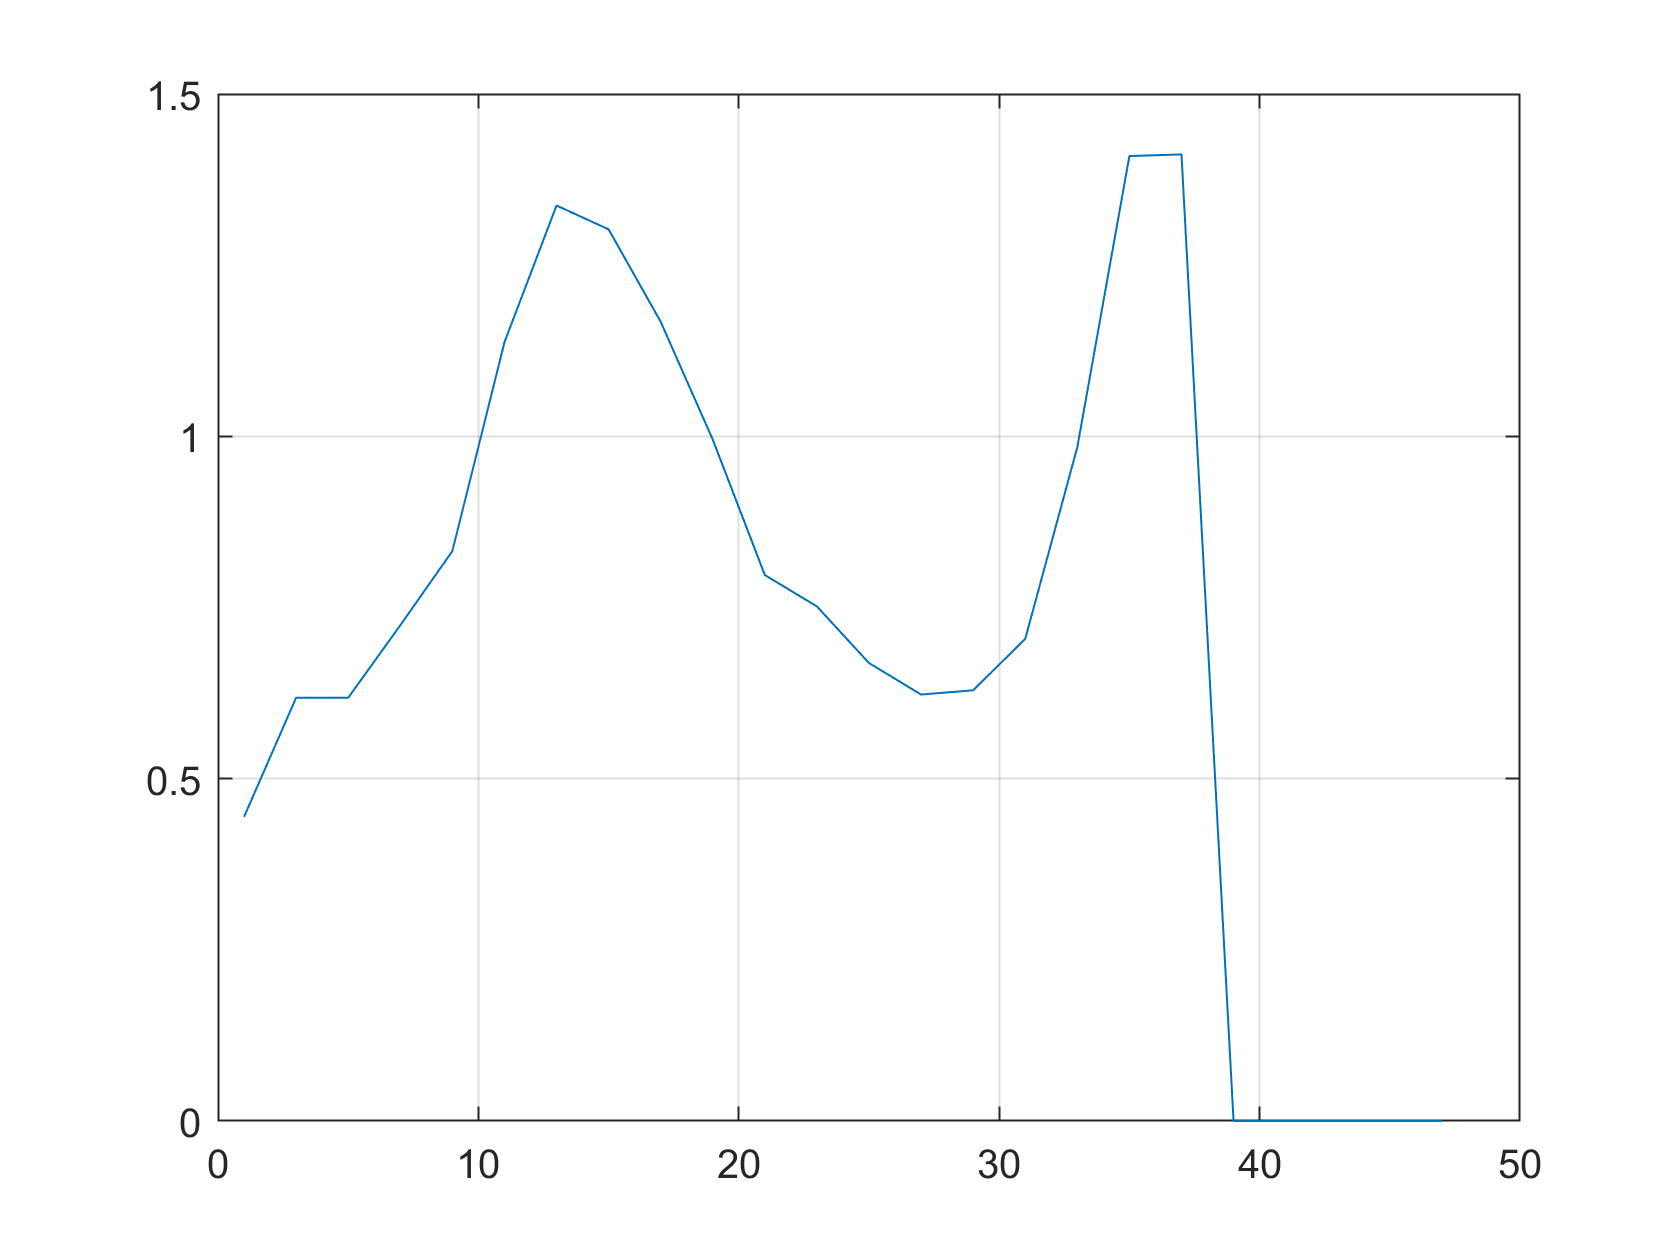


figure
plot(1:2:48,Uls)
grid on

**More advanced solution: Model Predictive Control**

You could formulate the MPC as a quadratic optimization problem, for some prediction and control horizon


$$\arg\min_U \frac{1}{2}U^\top G U + b^\top U$$


where 

$\underline{U}\le u(k) \le \overline{U}$ control input constraints

$\underline{y}-\overline{f}\le H(k)U(k) \le \overline{y} - \overline{f}$, output constraints

and input change rate constraints if applicable.

In the above equations

- 
$$G = 2(H^\top H + \lambda I)$$


- $b^\top = 2(\overline{f}-w)^\top H$, $w$ is the reference signal

- $\overline{f} = f + \hat{n}$, where $f$ is the future responses vector (due to past inputs) and $\hat{n}$ is the error.

% during the first iteration
l = 10;
f = 0;
G = 2*(H'*H + l*eye(24))

G =    20.2830    0.0612    0.0266    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0
    0.0612   20.1758    0.0952    0.0172    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0018    0.0004    0.0000    0.0000    0.0000    0.0000         0         0         0         0
    0.0266    0.0952   20.4145    0.0754    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0010    0.0009    0.0001    0.0000    0.0000    0.0000         0         0         0         0
    0.0000    0.0172    0.0754   20.4775    0.0312    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0
    0.0000    0.0000    0.0001  

b = 2*(f-w)'*H

b =    -0.1809   -0.2089   -0.3829   -0.4291   -0.2890   -0.3439   -0.1818   -0.0636   -0.0705   -0.0622   -0.0959   -0.1082   -0.1371   -0.2355   -0.2749   -0.3475   -0.3953   -0.2063   -0.0453   -0.0000         0         0         0         0



Umpc = quadprog(G,b,-H,-w,[],[],zeros(24,1),2*ones(24,1))


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Umpc =     0.5962
    0.5673
    0.6432
    0.7303
    0.8841
    1.2951
    1.3347
    1.3005
    1.1659
    0.9939


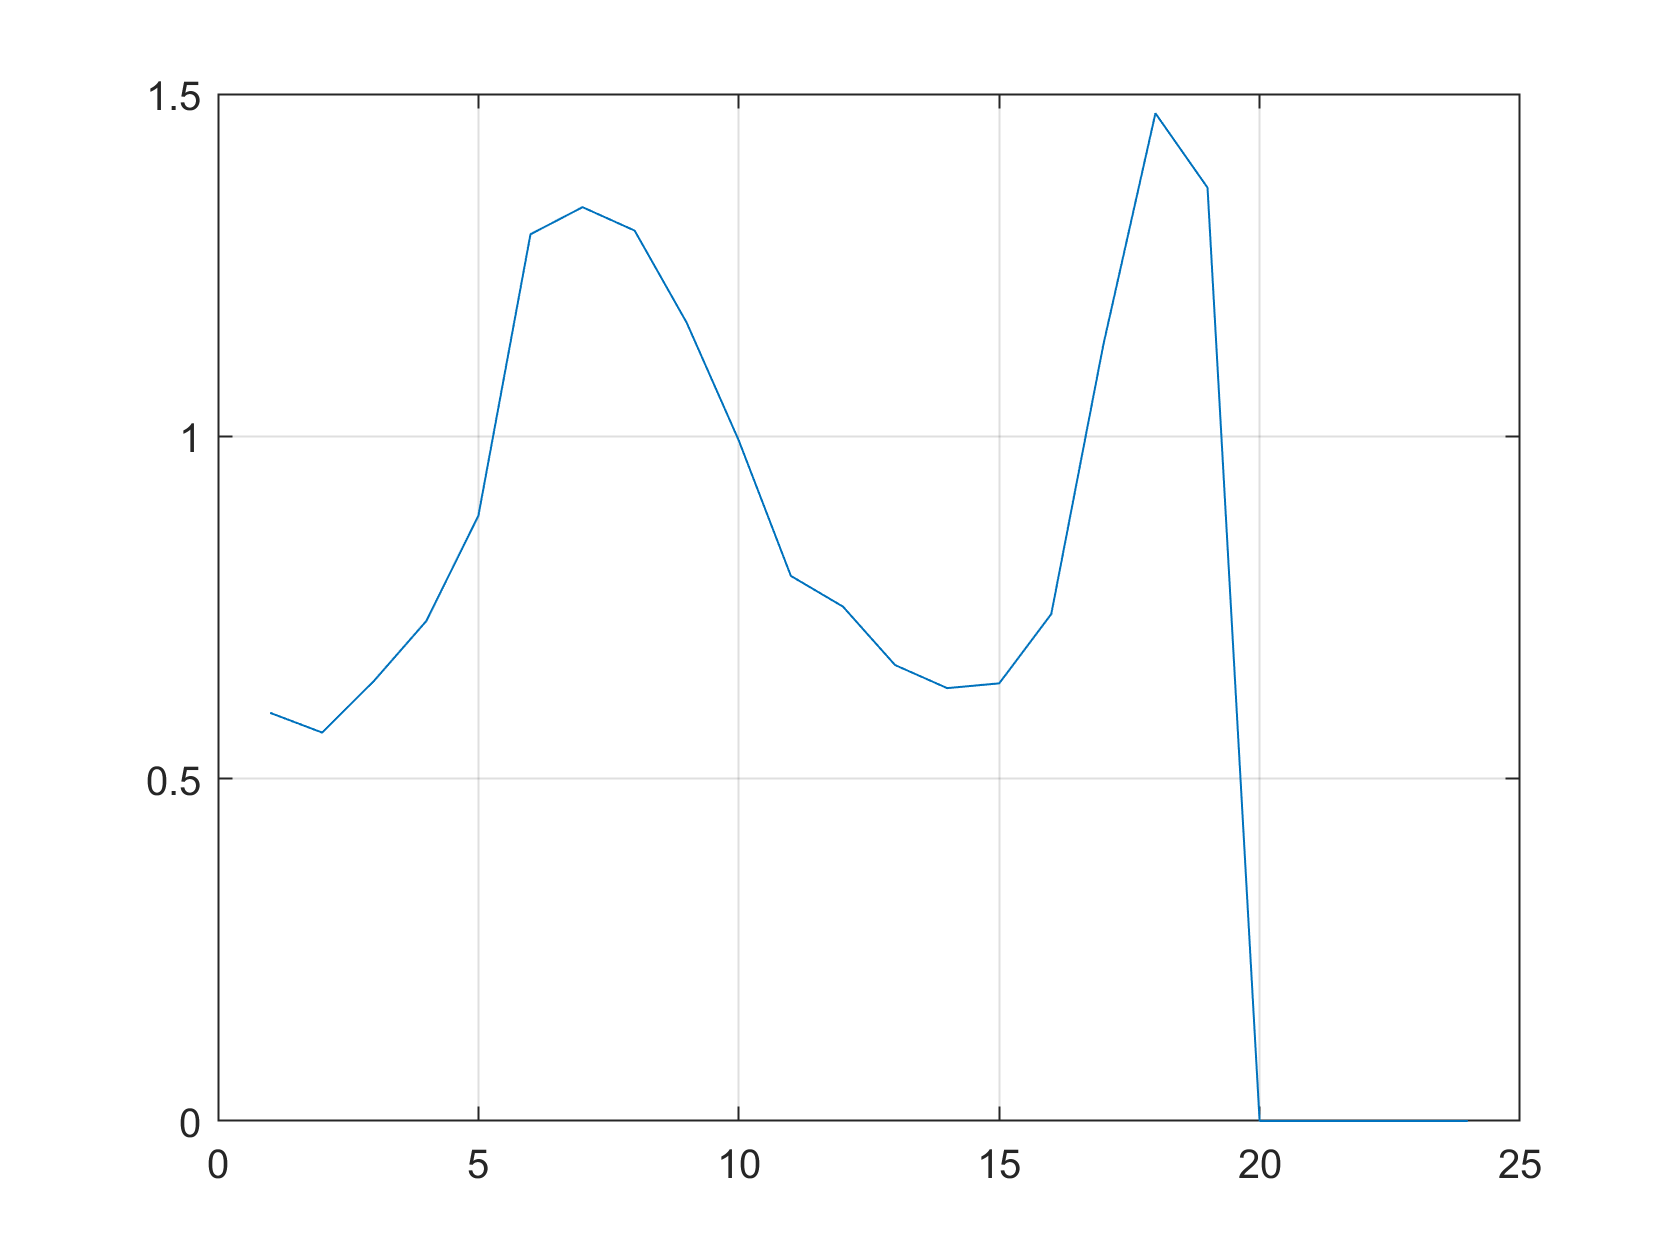


figure
plot(Umpc)
grid on

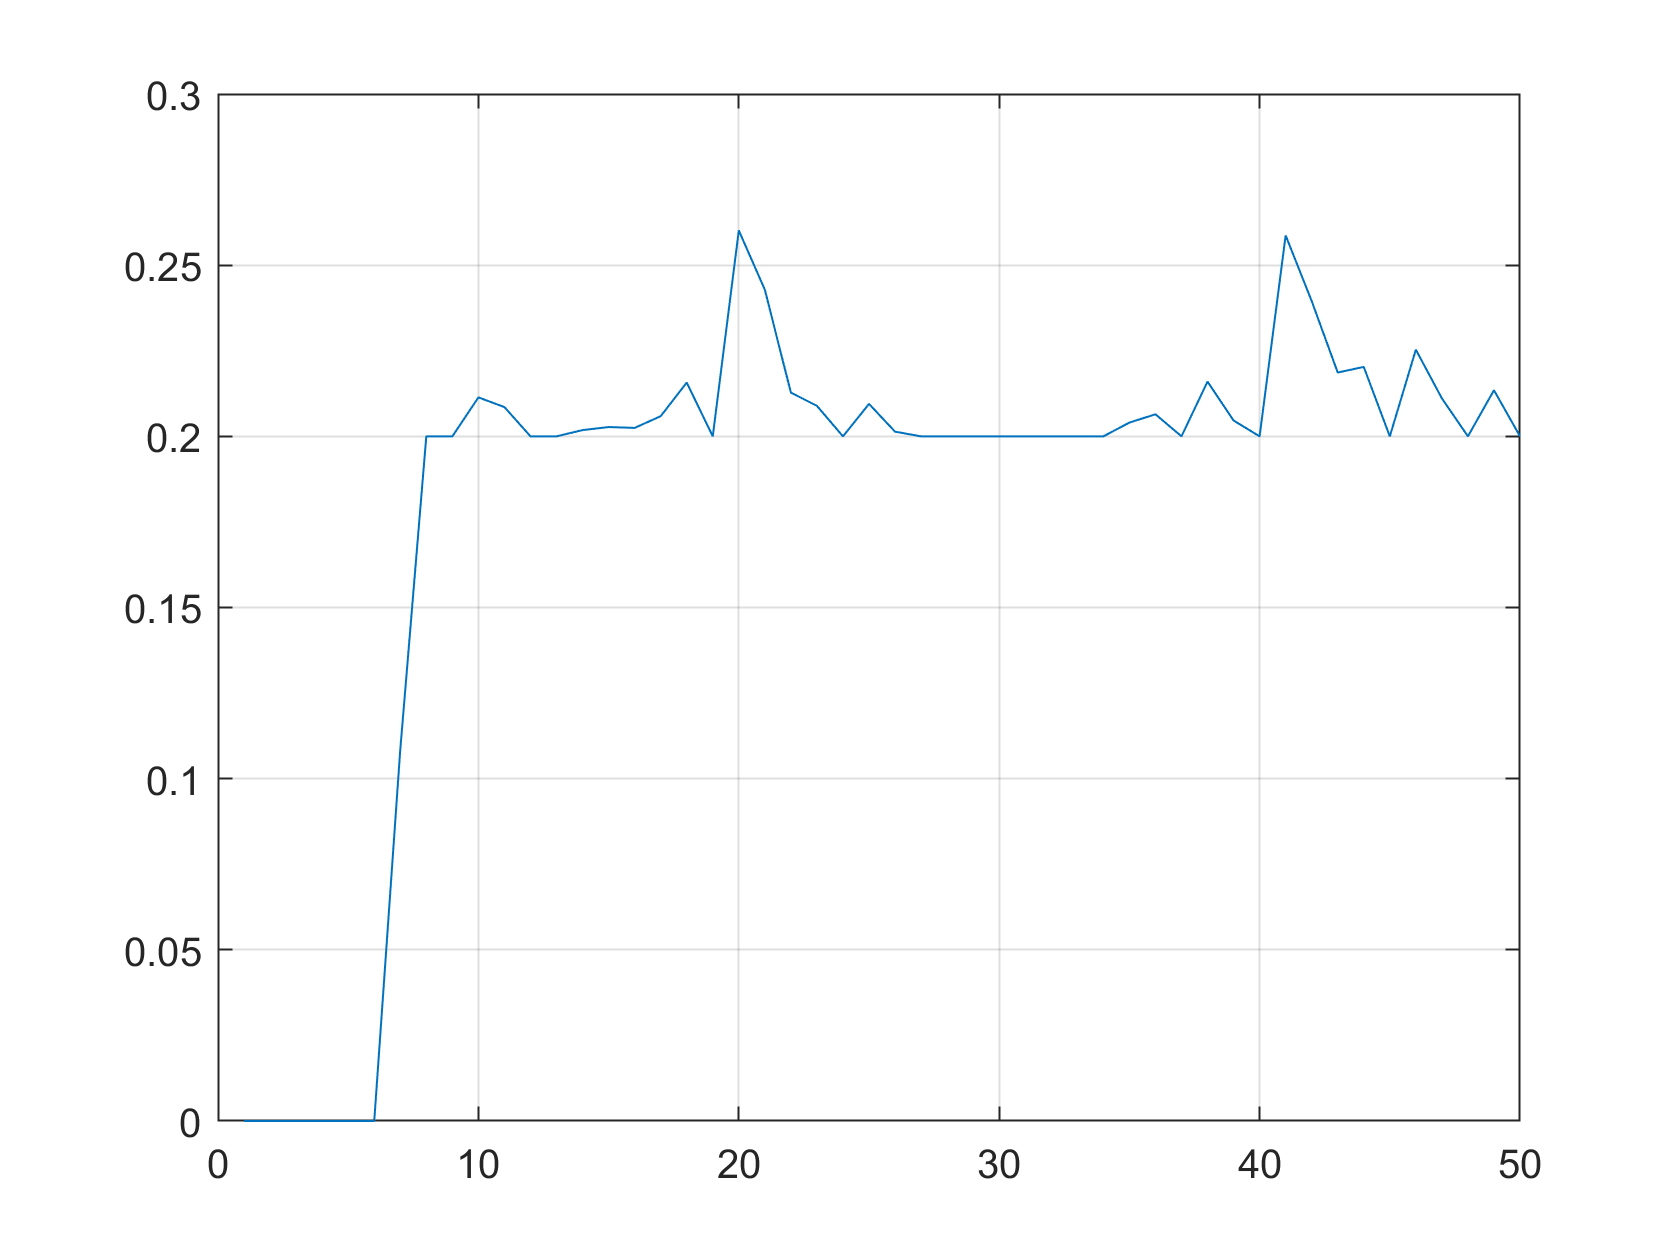


figure
plot(H*Umpc)
grid on

**Next step, you apply the next u(k), compute **$f$** and repeat the procedure for the next window in the future.**

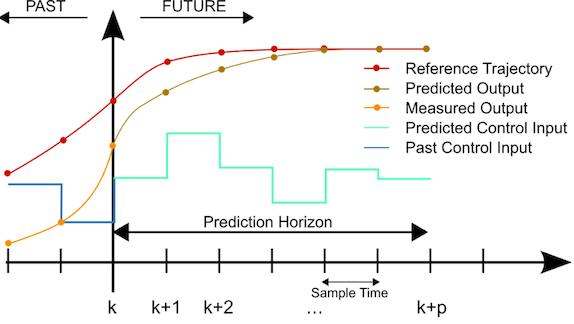

## Virtual City Benchmark

- KIOS has developed a virtual city, as part of the Teaming Project

- You can try all the challenges on that network

G = epanet('L-TOWN.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "L-TOWN.inp"...
Input File "L-TOWN.inp" loaded sucessfuly.


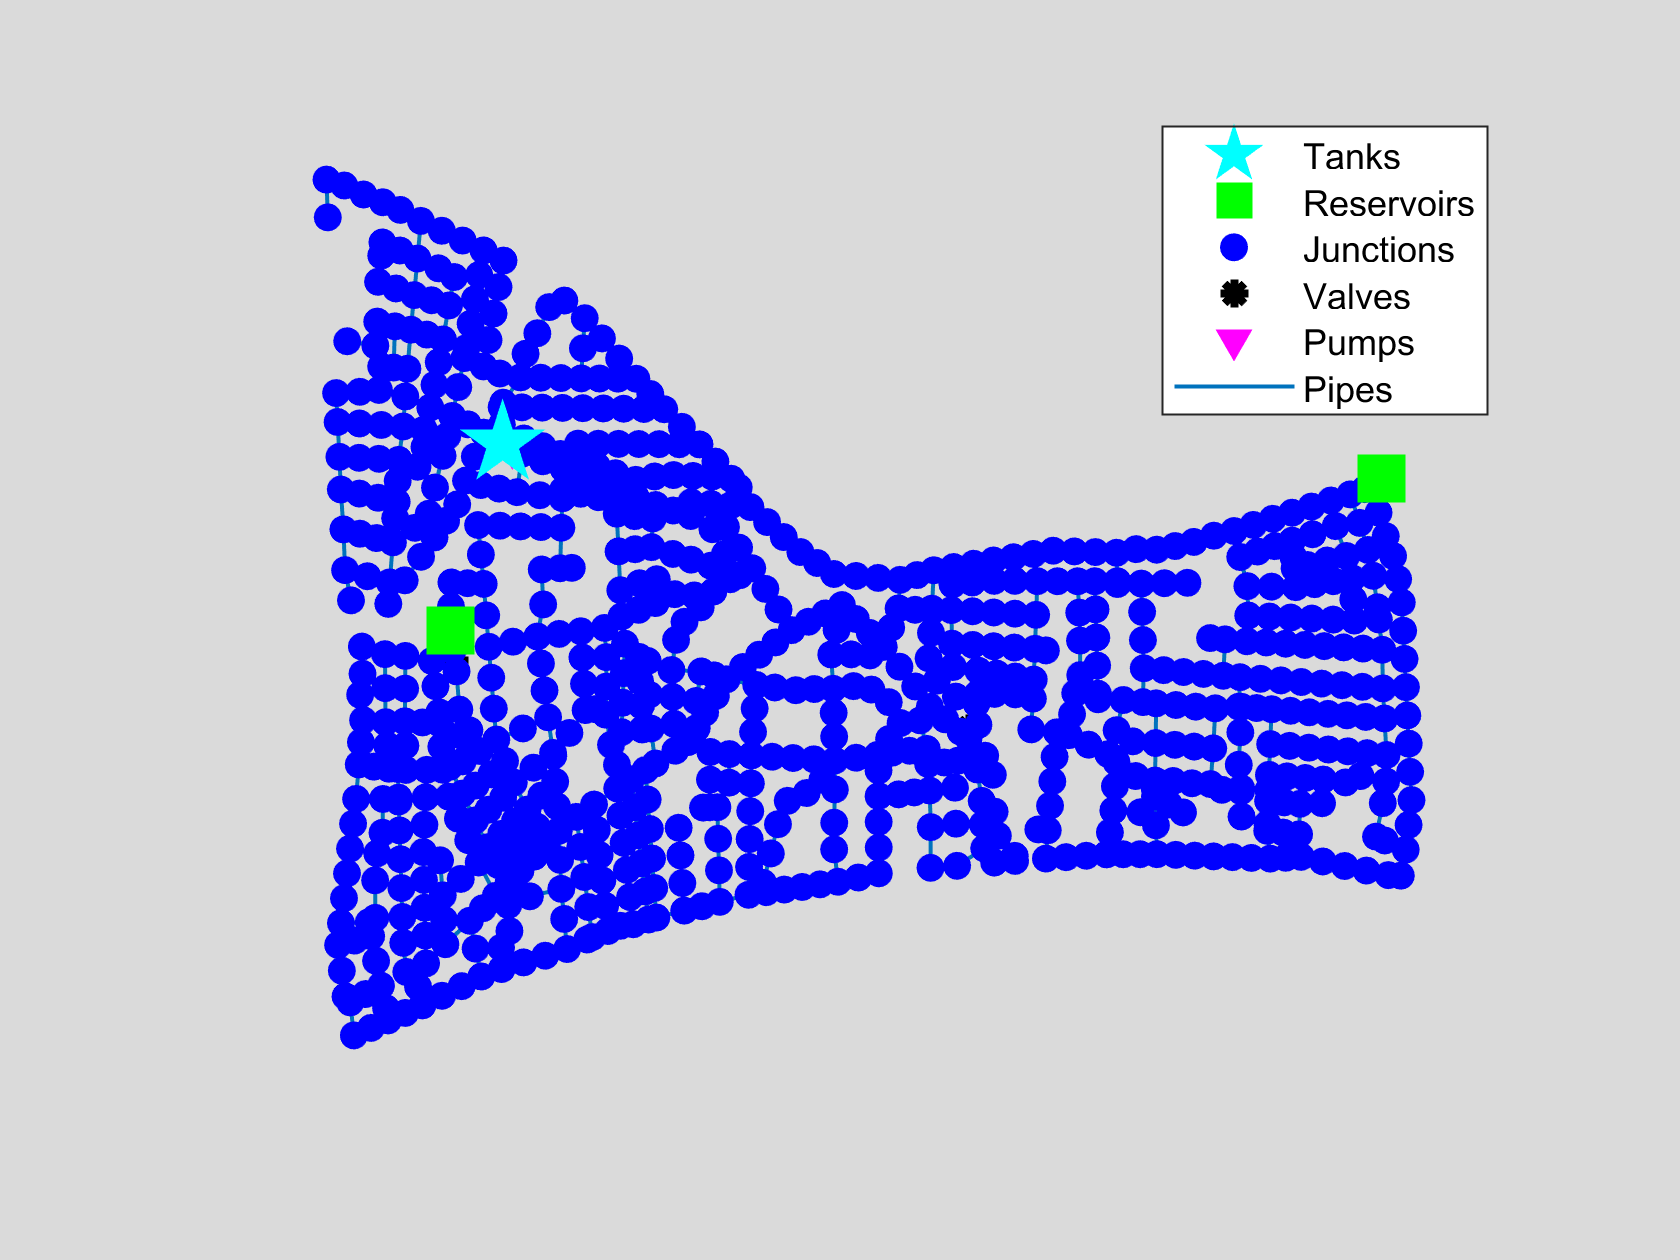

figure
G.plot;